# Trilateration Using Transmitters and Receivers

[Jerry Landivar G.](https://www.linkedin.com/in/jerry-land%C3%ADvar-guartatanga-0812b8231/), [Carolina Ormaza C.](https://www.linkedin.com/in/carolina-elizabeth-ormaza-castillo-789487212/), [Verónica Ojeda C.](https://www.fiec.espol.edu.ec/es/cv/ojeda-carrera-ver%C3%B3nica-jacqueline), [Víctor Asanza](https://orcid.org/0000-0002-2786-4162), [Juan Carlos Aviles](https://www.fiec.espol.edu.ec/es/cv/avil%C3%A9s-castillo-juan-carlos)

- Main Code: [https://github.com/vasanza/EnergyConsumptionPrediction](https://github.com/vasanza/EnergyConsumptionPrediction)

- `SRC: `[https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- `DataPort: `[https://dx.doi.org/10.21227/x6jw-m015](https://dx.doi.org/10.21227/x6jw-m015)

- `Reference: `[10.1109/SAS51076.2021.9530151](https://doi.org/10.1109/SAS51076.2021.9530151)

- Sampling Rate=1Hz

- Date = '2021-05-06 00:00:00' AND '2021-11-22 22:04:21'

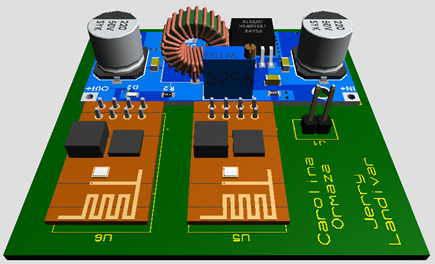

# 1- Load Raw Data

clear;clc;%clear all
%Prepare the raw dataset
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder
filenames = FindCSV(datapath);%List All CSV files
allData=[];
for i=1:length(filenames)% Through all files
    data=readtable(fullfile(datapath,filenames(i).name));%Select i CSV file
    %The first 3 columns are deleted: topic, server date, esp32 date, and esp32 date.
    data=[data(:,2) data(:,5:end)];
    dataNew=table2array(data);% Array Double
    dataNew(isnan(dataNew)) = 0;%Remove NAN numbers
    allData=[allData;dataNew];
end
clear data dataNew;

# 2- Every 60 samples the value of 1 minute is averaged

win=60;% 1 minute
%It takes time to iterate the number of samples / time window.
allDataMean = fData_MeanWin(allData,win);
%save(fullfile(datapath,'allData.mat'),'allData');%No es posible para datos
%mayores a 2GB
save(fullfile(datapath,'allDataMean.mat'),'allDataMean');
clear allData win

# 3- Plot Raw Data (Dataset)

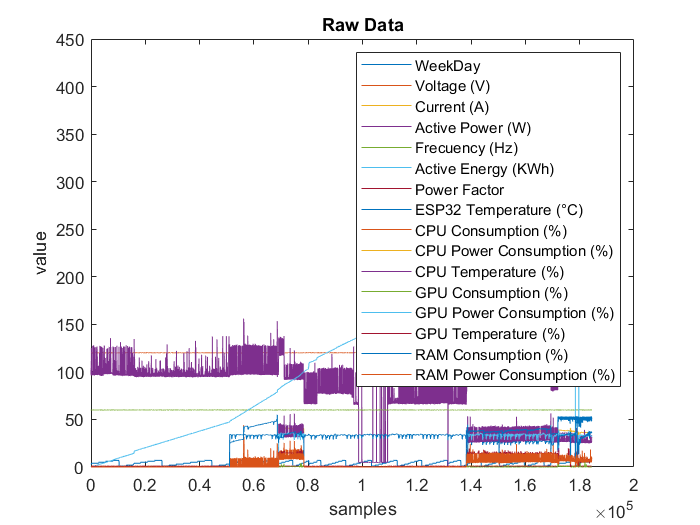

figure
plot(allDataMean);title('Raw Data');xlabel('samples');ylabel('value');
legend('WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)','Power Factor',...
    'ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)','GPU Consumption (%)'...
    ,'GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)');

# [4] - Feature Extraction (Please set TimeStep per time window)

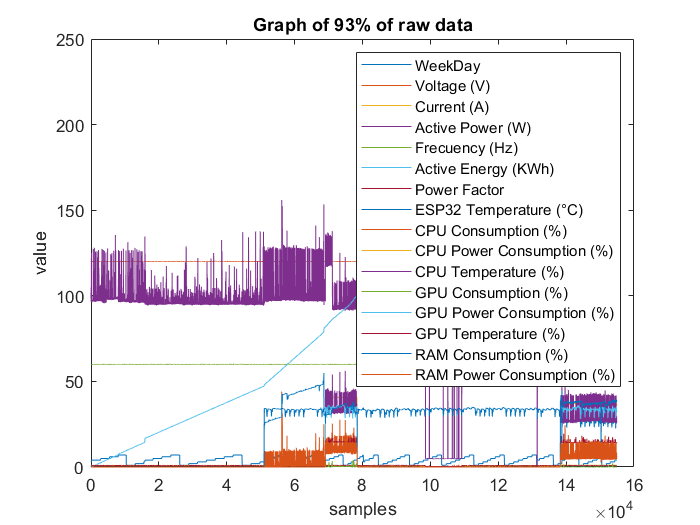

clear;clc;%clear all
%Prepare the raw dataset
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder
allDataMean = load(fullfile(datapath,'allDataMean.mat'));%List All CSV files
allDataMean=allDataMean.allDataMean;
allDataMean=allDataMean(1:round(size(allDataMean,1)*.84),:);%Eliminates the final 16% with noise (.93)
figure
plot(allDataMean);title('Graph of 93% of raw data');xlabel('samples');ylabel('value');
legend('WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)',...
    'Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)'...
    ,'GPU Consumption (%)','GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)');

AEds = datastats(allDataMean(:,6))%Active Energy Statistics with cumulative values

AEds = struct with fields:
       num: 154918
       max: 222.2872
       min: 0.0062
      mean: 97.2140
    median: 97.7100
     range: 222.2810
       std: 63.5079


%<----------------------------- Please select only one TimeStep
n = input(['Please select only one number (minute = 1,' ...
    ' hour = 2, day = 3, week = 4, month = 5),: ']);

switch n
    case 1
        TimeStep =1;% one minute
        disp('TimeStep selected is minute')
    case 2
        TimeStep =60;% one hour in minutes
        disp('TimeStep selected is hour')
    case 3
        TimeStep =1440;% one day in minutes (ok)
        disp('TimeStep selected is day')
    case 4
        TimeStep =10080;% one week in minutes (ok)
        disp('TimeStep selected is week')
    case 5
        TimeStep =40320;% one month in minutes (only 8 monthss) (ok)
        disp('TimeStep selected is month')
    otherwise
        disp('other value')
end

TimeStep selected is day


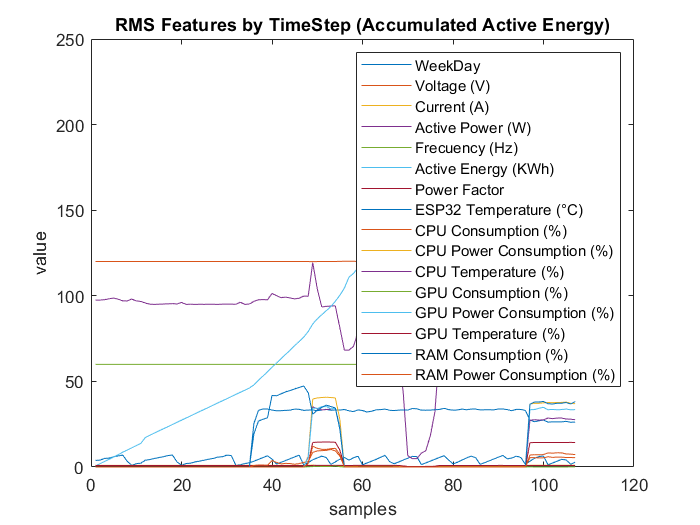


figure; DataFeatures = frms_features_v2(allDataMean,TimeStep);
plot(DataFeatures);title('RMS Features by TimeStep (Accumulated Active Energy)');xlabel('samples');ylabel('value');
legend('WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)',...
    'Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)'...
    ,'GPU Consumption (%)','GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)');

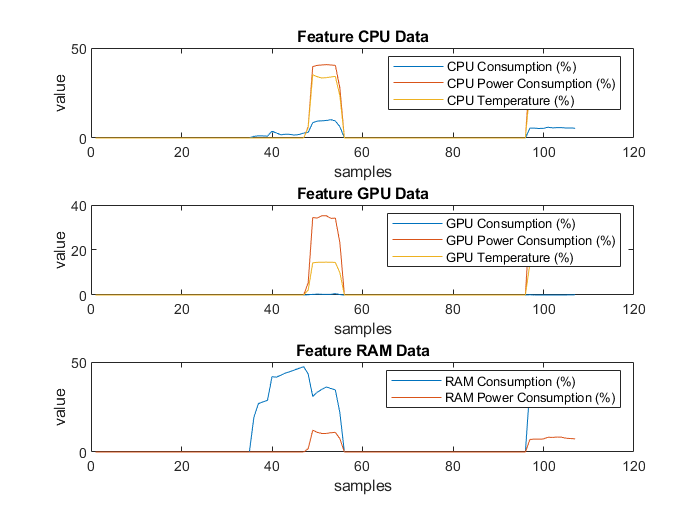

figure; subplot(3,1,1)
plot(DataFeatures(:,9:11));title('Feature CPU Data');xlabel('samples');ylabel('value');
legend('CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)');
subplot(3,1,2)
plot(DataFeatures(:,12:14));title('Feature GPU Data');xlabel('samples');ylabel('value');
legend('GPU Consumption (%)','GPU Power Consumption (%)','GPU Temperature (%)');
subplot(3,1,3)
plot(DataFeatures(:,15:16));title('Feature RAM Data');xlabel('samples');ylabel('value');
legend('RAM Consumption (%)','RAM Power Consumption (%)');

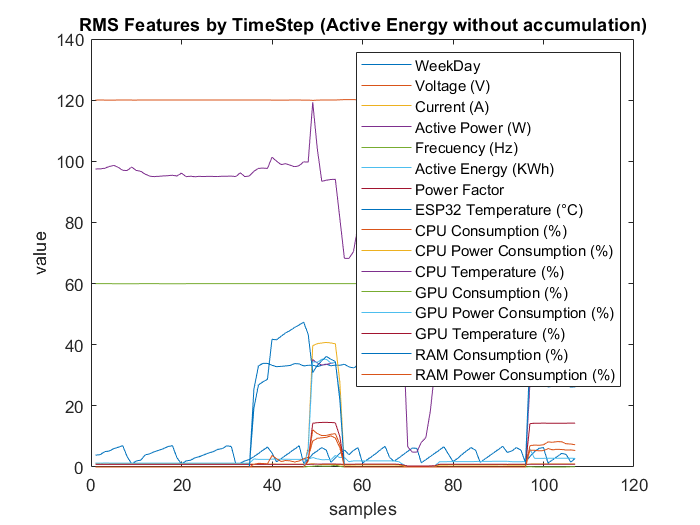

figure; DataFeatures(:,6)= fmax_features(allDataMean(:,6),TimeStep);
DataFeatures(:,6)=hampel(DataFeatures(:,6));
plot(DataFeatures);title('RMS Features by TimeStep (Active Energy without accumulation)');xlabel('samples');ylabel('value');
legend('WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)',...
    'Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)'...
    ,'GPU Consumption (%)','GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)');

AEds = datastats(DataFeatures(:,6))%Active Energy (KWh), without accumulation (separated by time window)

AEds = struct with fields:
       num: 107
       max: 5.9600
       min: 0.1200
      mean: 1.8294
    median: 1.7700
     range: 5.8400
       std: 0.8477


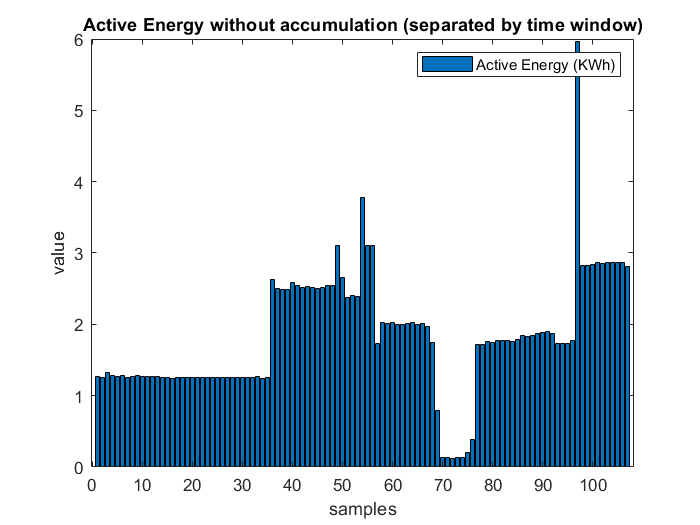

figure; bar(DataFeatures(:,6));title('Active Energy without accumulation (separated by time window)');xlabel('samples');ylabel('value');
legend('Active Energy (KWh)');

clear allDataMean TimeStep

# 5- Statital Features Information

%WeekDay','Voltage (V)'
[wds,vds] = datastats(DataFeatures(:,1),DataFeatures(:,2))

wds = struct with fields:
       num: 107
       max: 7
       min: 1
      mean: 4.1818
    median: 4.3336
     range: 6
       std: 1.7573


vds = struct with fields:
       num: 107
       max: 120.4916
       min: 119.9211
      mean: 120.0953
    median: 120.0544
     range: 0.5704
       std: 0.1254


%'Current (A)','Active Power (W)'
[cds,pds] = datastats(DataFeatures(:,3),DataFeatures(:,4))

cds = struct with fields:
       num: 107
       max: 1.0957
       min: 0.1300
      mean: 0.7993
    median: 0.9232
     range: 0.9657
       std: 0.2216


pds = struct with fields:
       num: 107
       max: 119.3349
       min: 4.8674
      mean: 84.6613
    median: 95.0447
     range: 114.4675
       std: 24.0662


%'Frecuency (Hz)','Active Energy (KWh)'
[fds,eds] = datastats(DataFeatures(:,5),DataFeatures(:,6))

fds = struct with fields:
       num: 107
       max: 59.9695
       min: 59.9599
      mean: 59.9648
    median: 59.9647
     range: 0.0097
       std: 0.0021


eds = struct with fields:
       num: 107
       max: 5.9600
       min: 0.1200
      mean: 1.8294
    median: 1.7700
     range: 5.8400
       std: 0.8477


%'Power Factor','ESP32 Temperature (°C)'
[pfds,tds] = datastats(DataFeatures(:,7),DataFeatures(:,8))

pfds = struct with fields:
       num: 107
       max: 0.9620
       min: 0.3201
      mean: 0.8507
    median: 0.8687
     range: 0.6418
       std: 0.1406


tds = struct with fields:
       num: 107
       max: 34.3069
       min: 0
      mean: 21.6780
    median: 32.8821
     range: 34.3069
       std: 15.3350


%'CPU Consumption (%)','CPU Power Consumption (%)'
[cpuds,cpupds] = datastats(DataFeatures(:,9),DataFeatures(:,10))

cpuds = struct with fields:
       num: 107
       max: 10.1948
       min: 0
      mean: 1.4073
    median: 0
     range: 10.1948
       std: 2.6973


cpupds = struct with fields:
       num: 107
       max: 40.7520
       min: 0
      mean: 6.4272
    median: 0
     range: 40.7520
       std: 14.2619


%'CPU Temperature (%)',%'GPU Consumption (%)'
[cputds,gpuds] = datastats(DataFeatures(:,11),DataFeatures(:,12))

cputds = struct with fields:
       num: 107
       max: 35.1698
       min: 0
      mean: 5.0551
    median: 0
     range: 35.1698
       std: 11.2423


gpuds = struct with fields:
       num: 107
       max: 0.5909
       min: 0
      mean: 0.0266
    median: 0
     range: 0.5909
       std: 0.0896


%'GPU Power Consumption (%)','GPU Temperature (%)'
[gpupds,gputds] = datastats(DataFeatures(:,13),DataFeatures(:,14))

gpupds = struct with fields:
       num: 107
       max: 35.2516
       min: 0
      mean: 5.6730
    median: 0
     range: 35.2516
       std: 12.5917


gputds = struct with fields:
       num: 107
       max: 14.5880
       min: 0
      mean: 2.3977
    median: 0
     range: 14.5880
       std: 5.3226


%'RAM Consumption (%)','RAM Power Consumption (%)'
[ramds,rampds] = datastats(DataFeatures(:,15),DataFeatures(:,16))

ramds = struct with fields:
       num: 107
       max: 47.3799
       min: 0
      mean: 10.6423
    median: 0
     range: 47.3799
       std: 17.1225


rampds = struct with fields:
       num: 107
       max: 12.1653
       min: 0
      mean: 1.4798
    median: 0
     range: 12.1653
       std: 3.3328


clear wds vds cds pds fds eds pfds tds cpuds cpupds cputds gpuds gpupds gputds ramds rampds

# 6- Feature Normalization and Plot

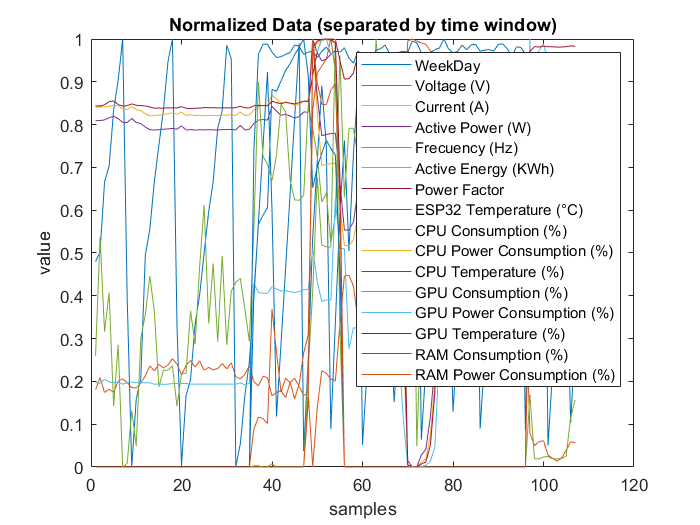

allFeatureNorm = fNormalization(DataFeatures);%Normalization
figure; plot(allFeatureNorm);title('Normalized Data (separated by time window)');xlabel('samples');ylabel('value');
legend('WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)',...
    'Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)'...
    ,'GPU Consumption (%)','GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)');

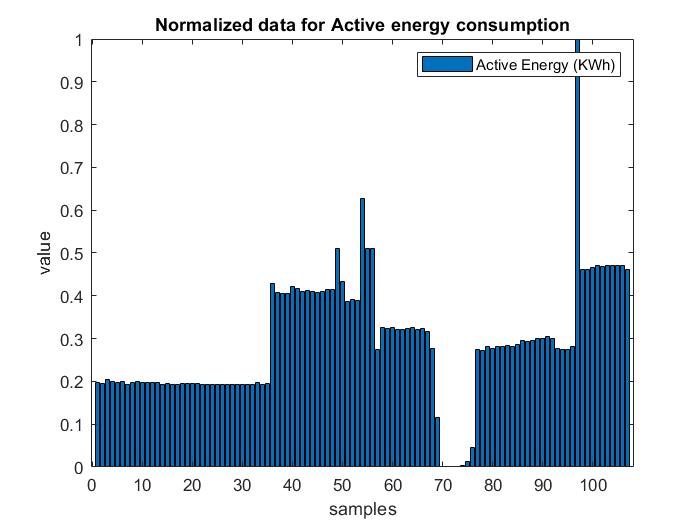

figure; bar(allFeatureNorm(:,6));title('Normalized data for Active energy consumption');xlabel('samples');ylabel('value');
legend('Active Energy (KWh)');

clear DataFeatures

# 7 - Feature Selection (Please set the maximum correlation value allowed.)

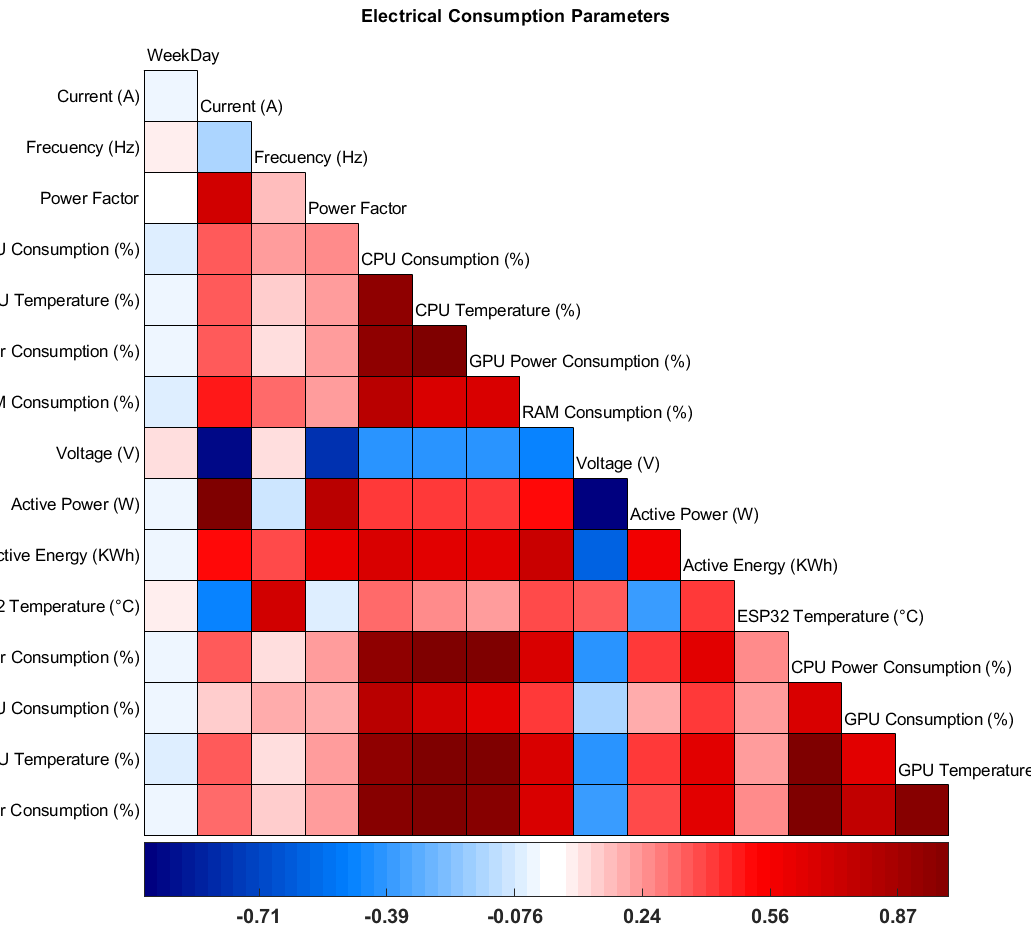

threshold = 0.75;%75<-------Maximum correlation value allowed
% Labels:
FeaturesLabels = {'WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)','Power Factor',...
    'ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)','GPU Consumption (%)'...
    ,'GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)'};
[NewDataFeatures,NewFeaturesLabels,LabelsRemove] = Feature_Selection(allFeatureNorm,FeaturesLabels,threshold);

LabelsRemove(:)

ans = 9×1 cell array
    {'Active Power (W)'         }
    {'Power Factor'             }
    {'CPU Power Consumption (%)'}
    {'CPU Temperature (%)'      }
    {'GPU Consumption (%)'      }
    {'GPU Power Consumption (%)'}
    {'GPU Temperature (%)'      }
    {'RAM Consumption (%)'      }
    {'RAM Power Consumption (%)'}


clear threshold LabelsRemove ans allFeatureNorm FeaturesLabels

# 8 - Regression Learner (Input output Data)

training_size=0.85; %70 Training, 15% Validation
Cell_Active_Energy=strfind(NewFeaturesLabels, 'Active Energy (KWh)');
ind_Active_Energy = find(not(cellfun('isempty',Cell_Active_Energy)));

% ---------------inputs: All previously selected features------------------
input_train=NewDataFeatures(1:round(size(NewDataFeatures,1)*training_size)-1,:);

% ----------------output: Energy in the next time step---------------------
output_train=NewDataFeatures(1+1:round(size(NewDataFeatures,1)*training_size),...
    ind_Active_Energy);%Active Energy index 5
%regressionLearner
clear Cell_Active_Energy Features_labels

# RMSE (Validation): 1 Week [threshold = 0.750;training_size=0.85;]

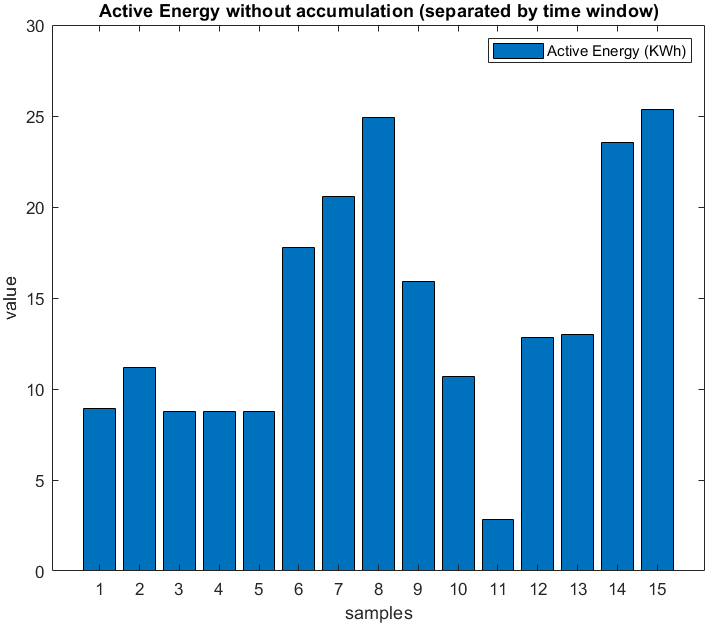

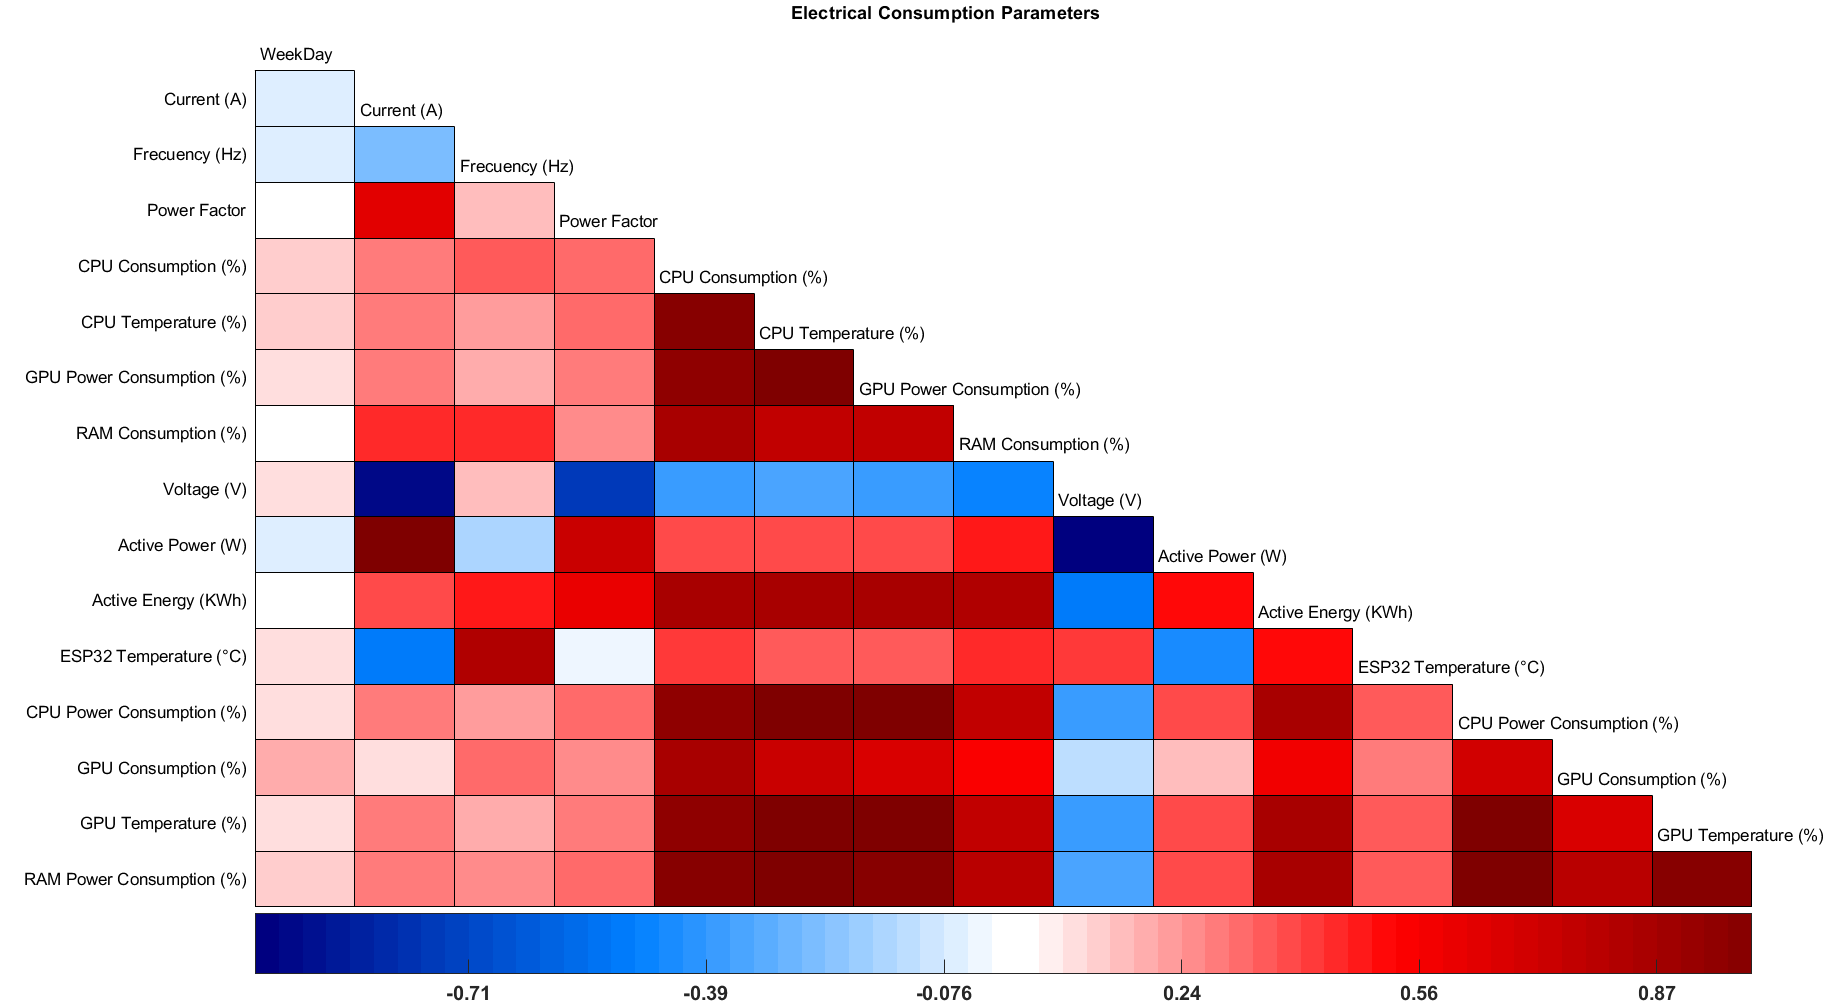

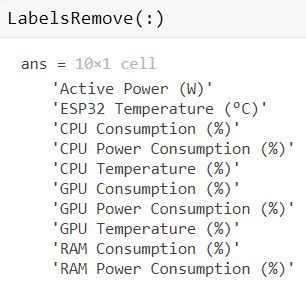

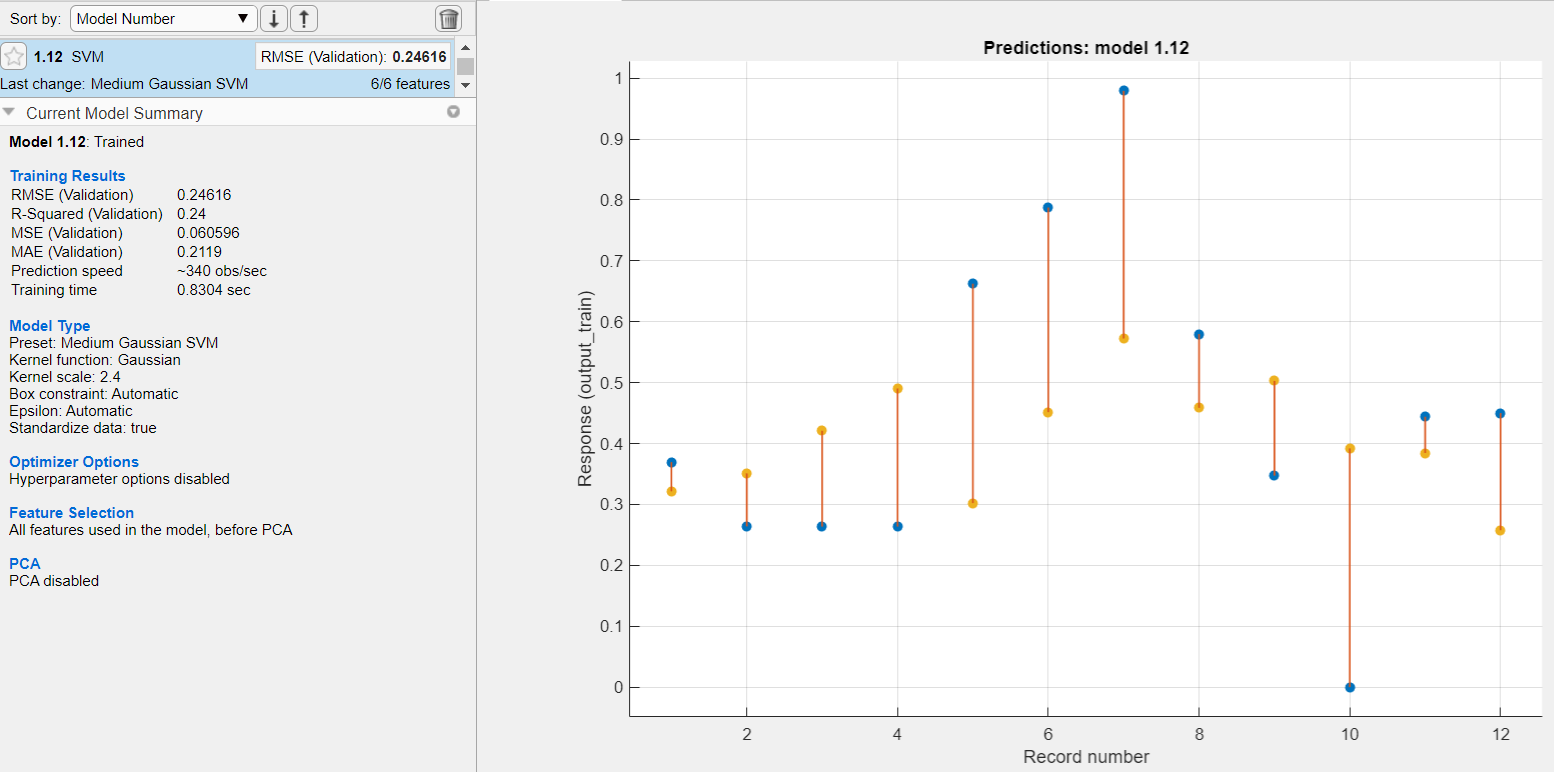

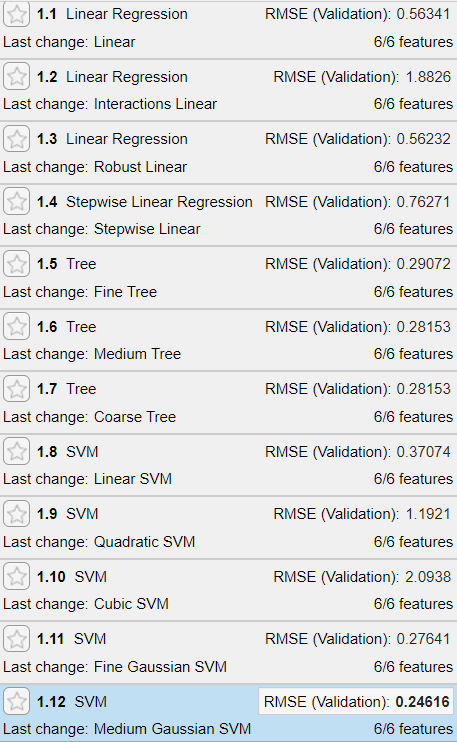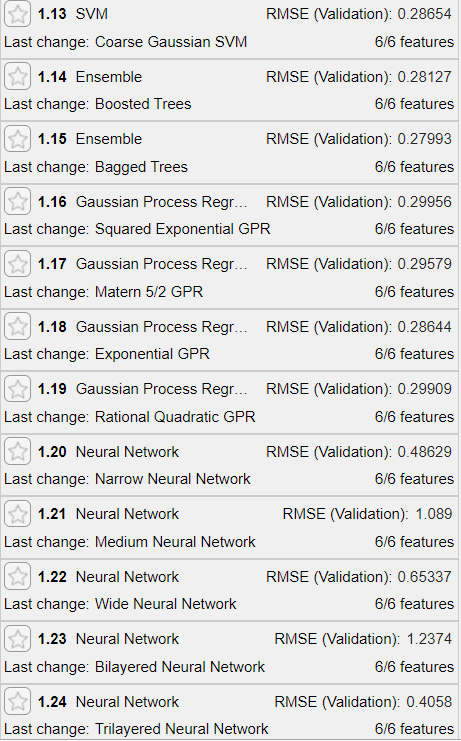

# RMSE (Validation - Filtrado): 1 Week [threshold = 0.750;training_size=0.85;]

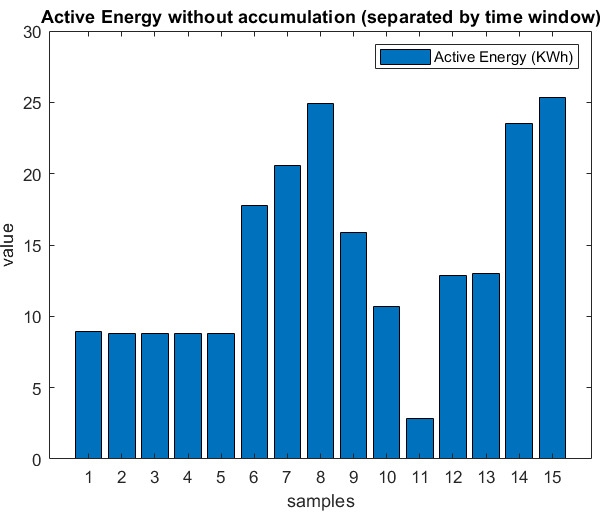

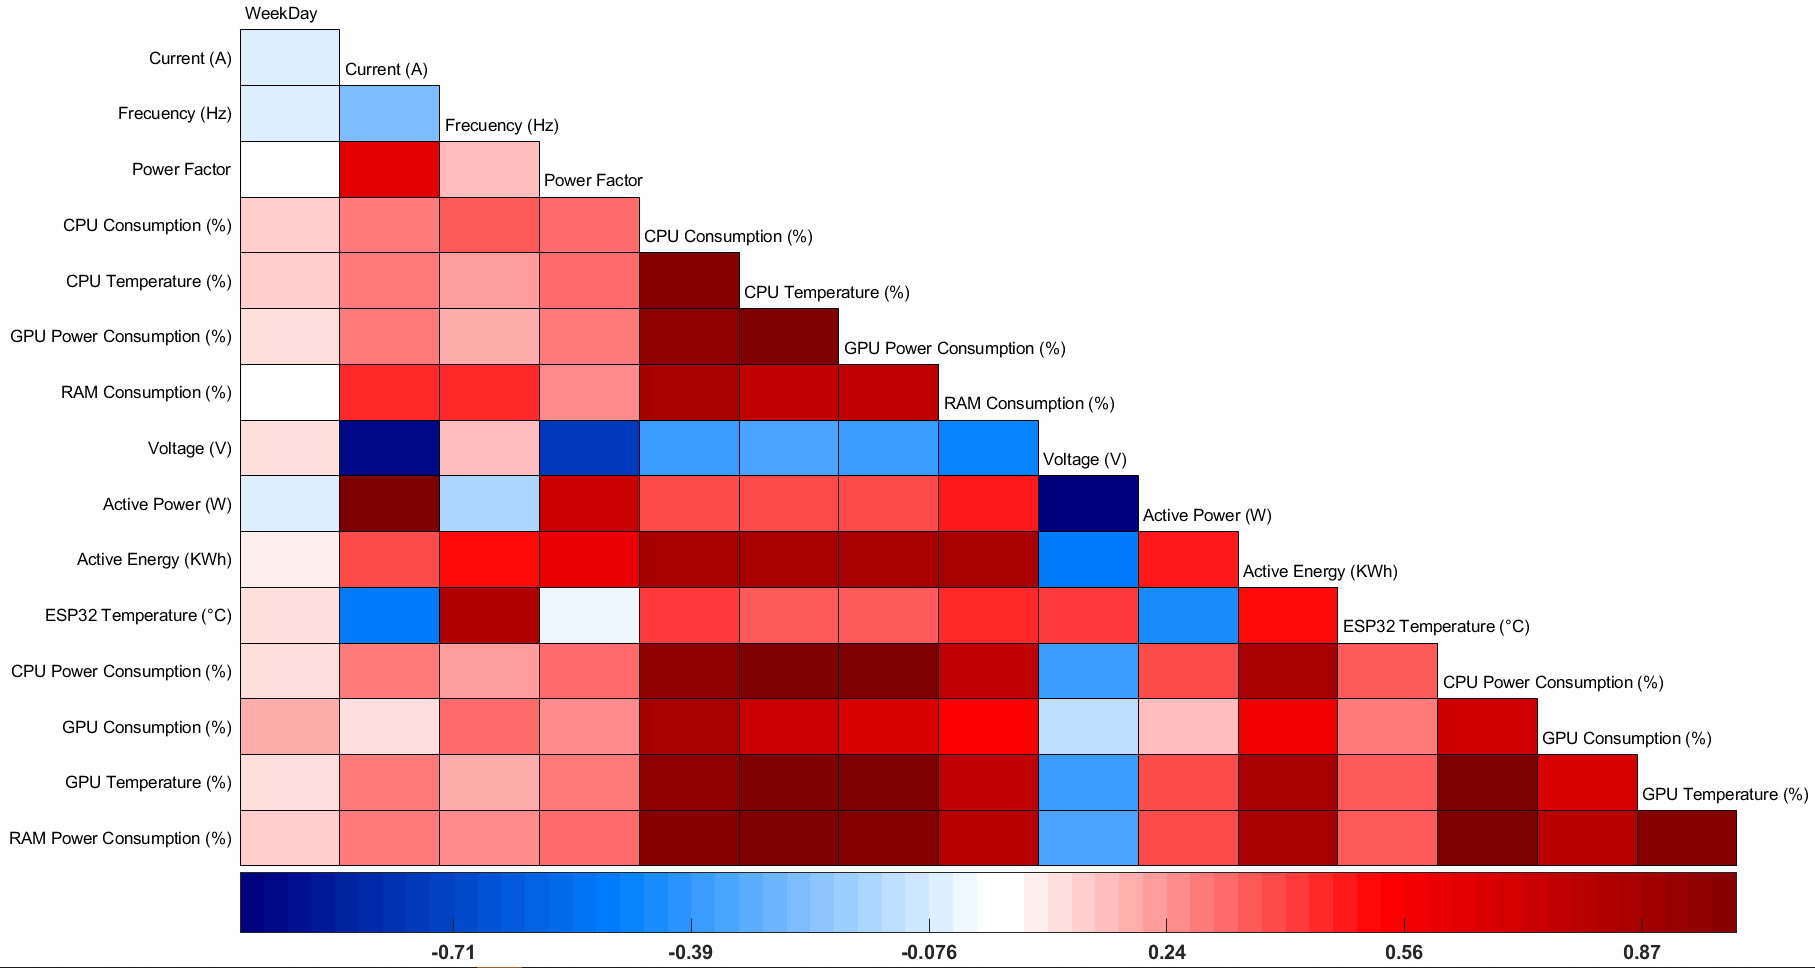

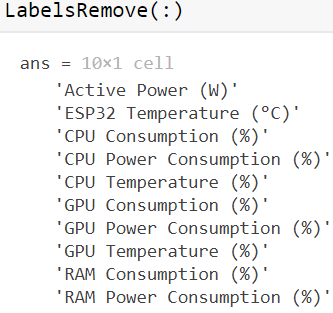

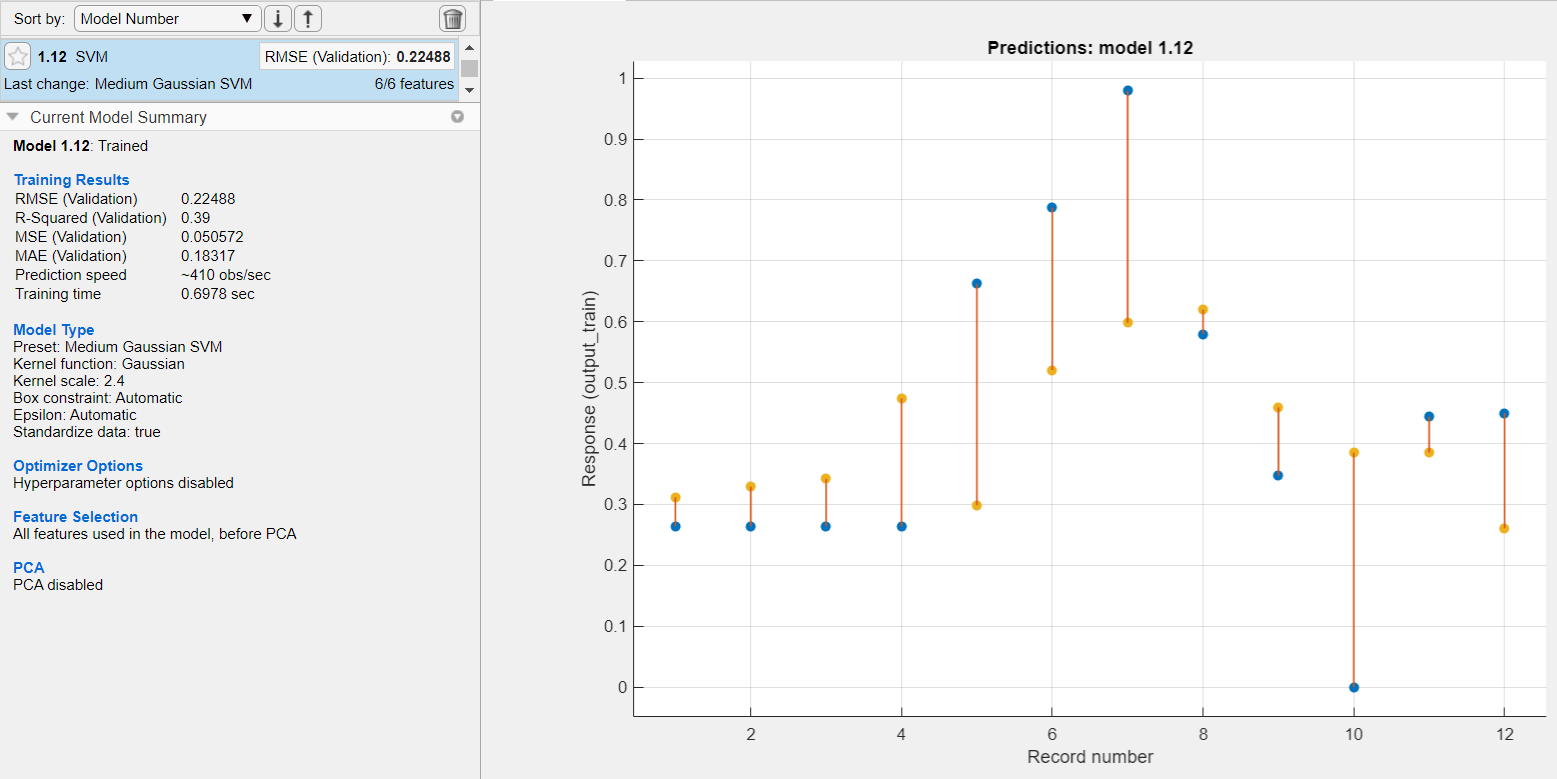

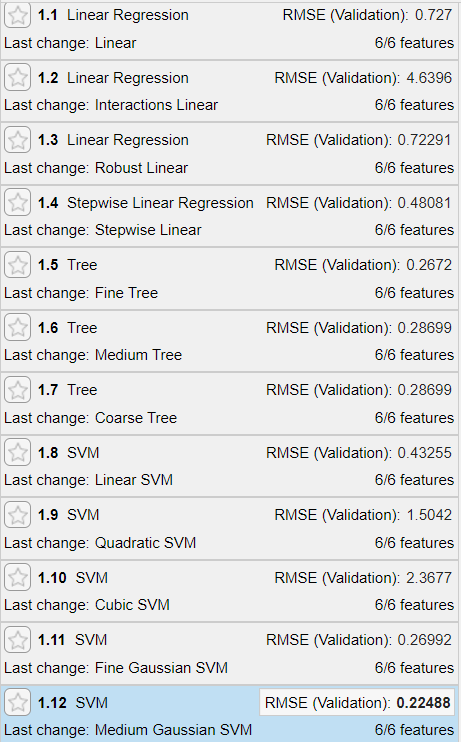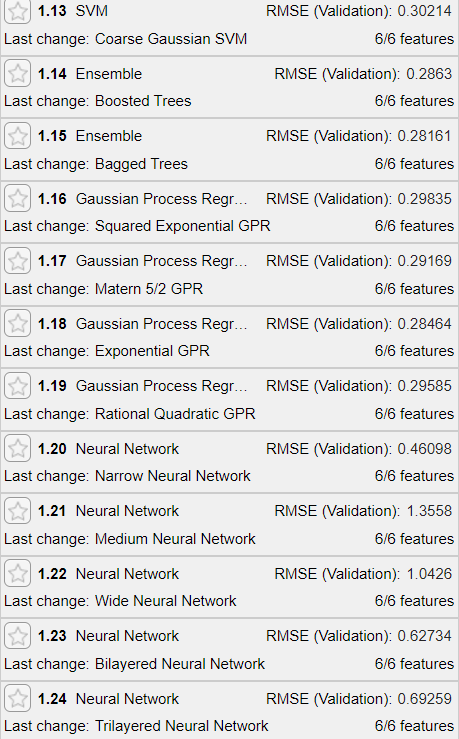

# RMSE (Validation): 1 day [threshold = 0.750;training_size=0.85;]

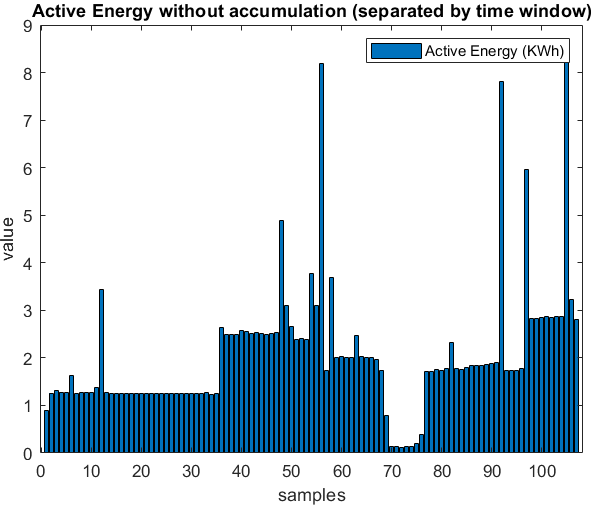

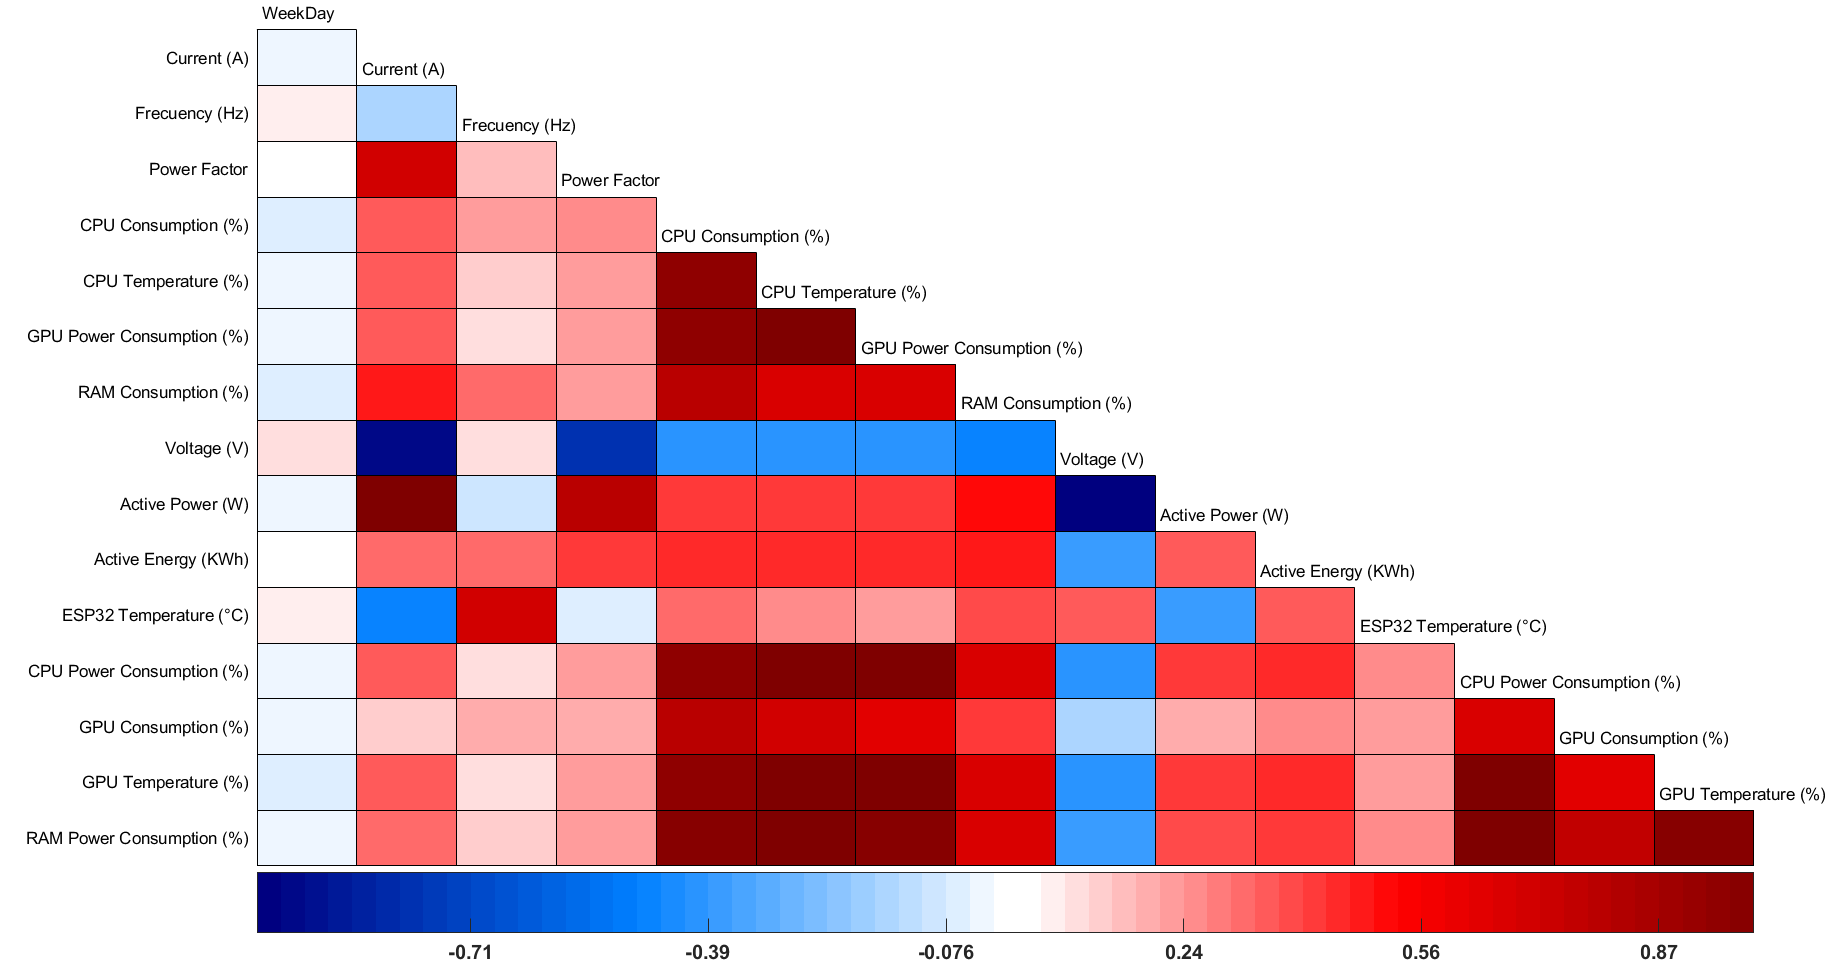

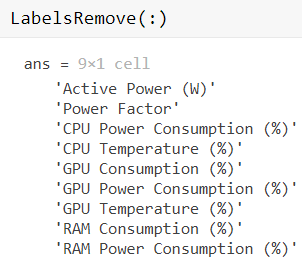

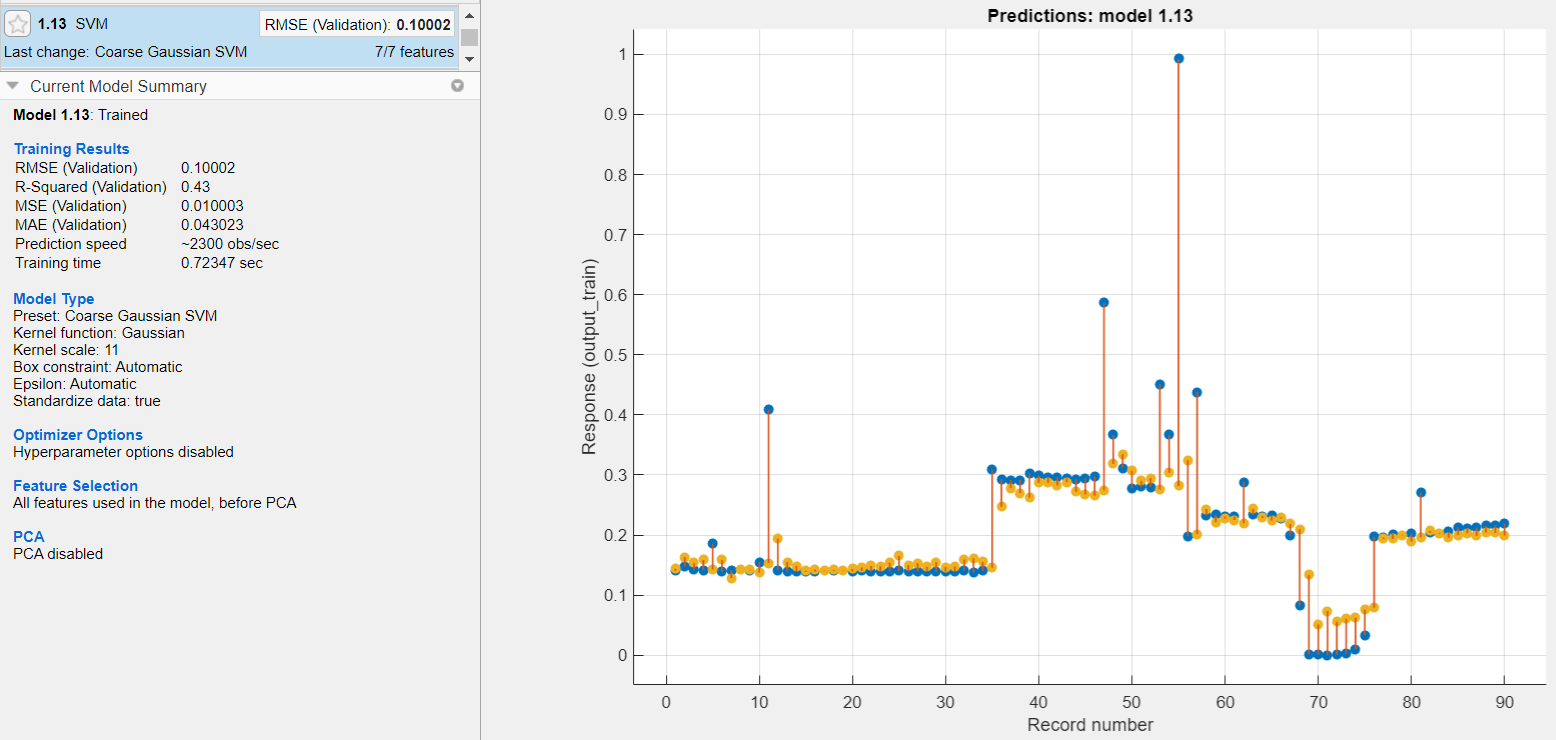

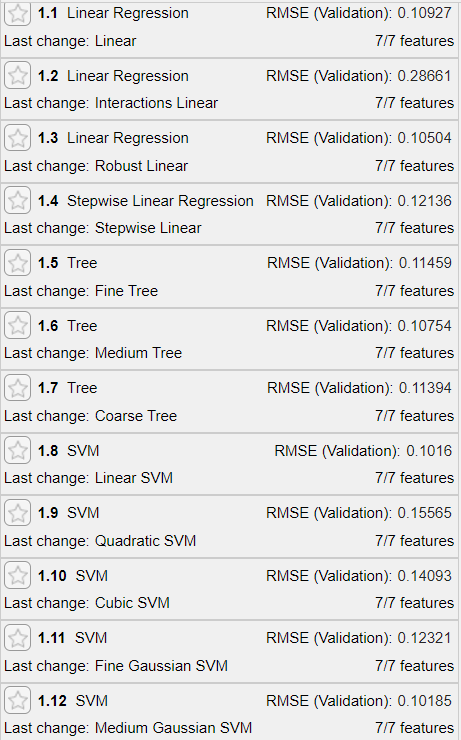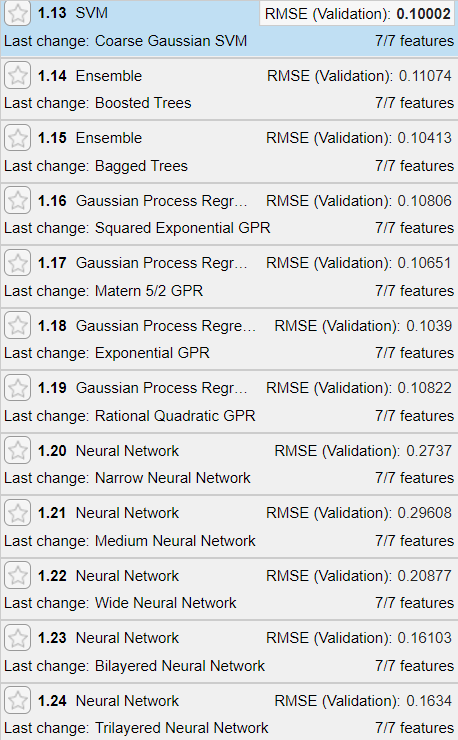

# RMSE (Validation - Filtrado): 1 day [threshold = 0.750;training_size=0.85;]

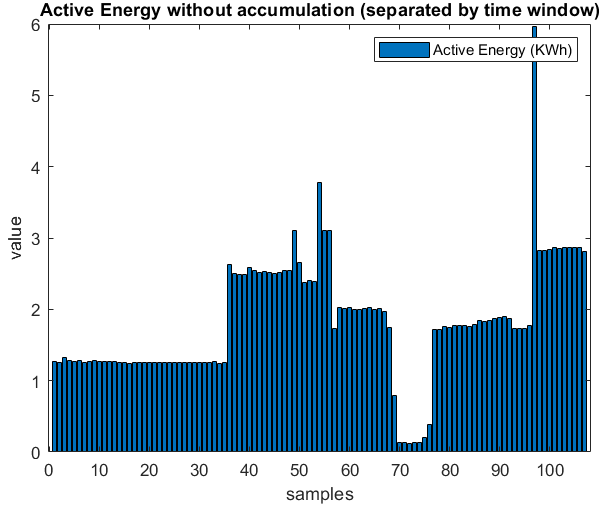

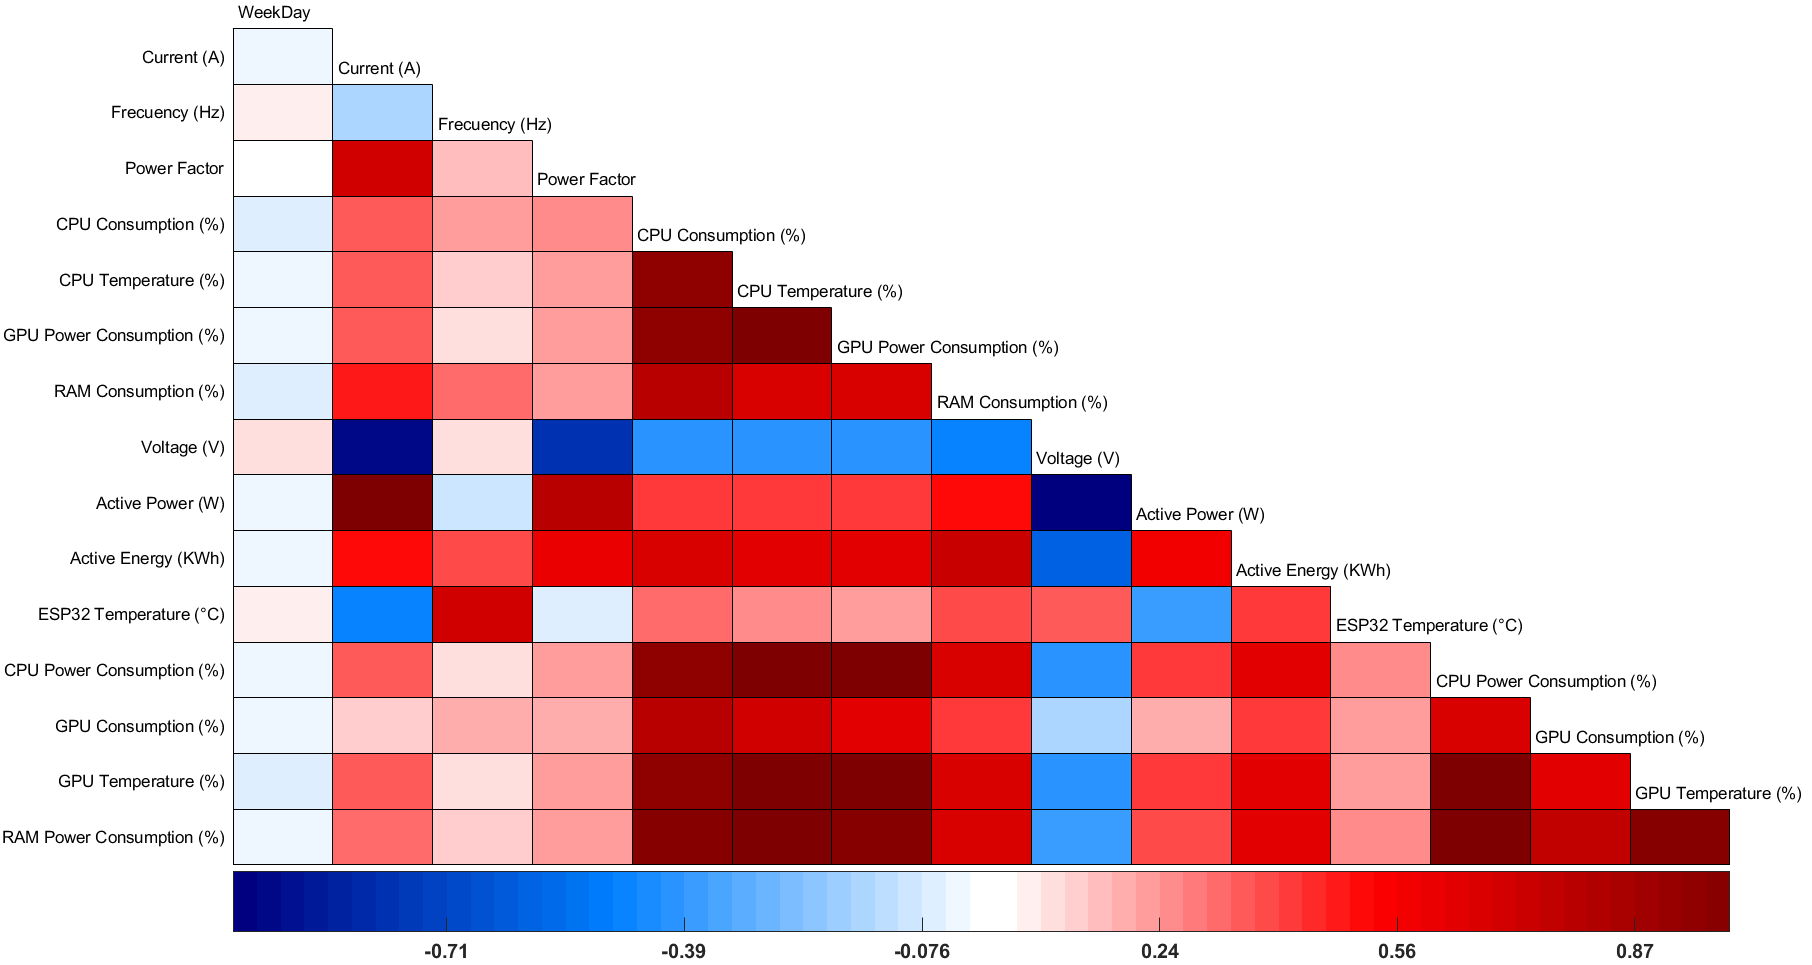

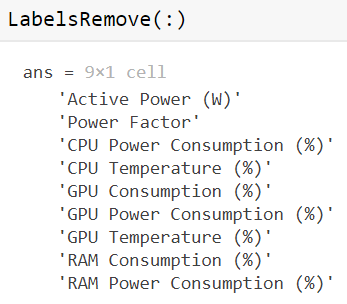

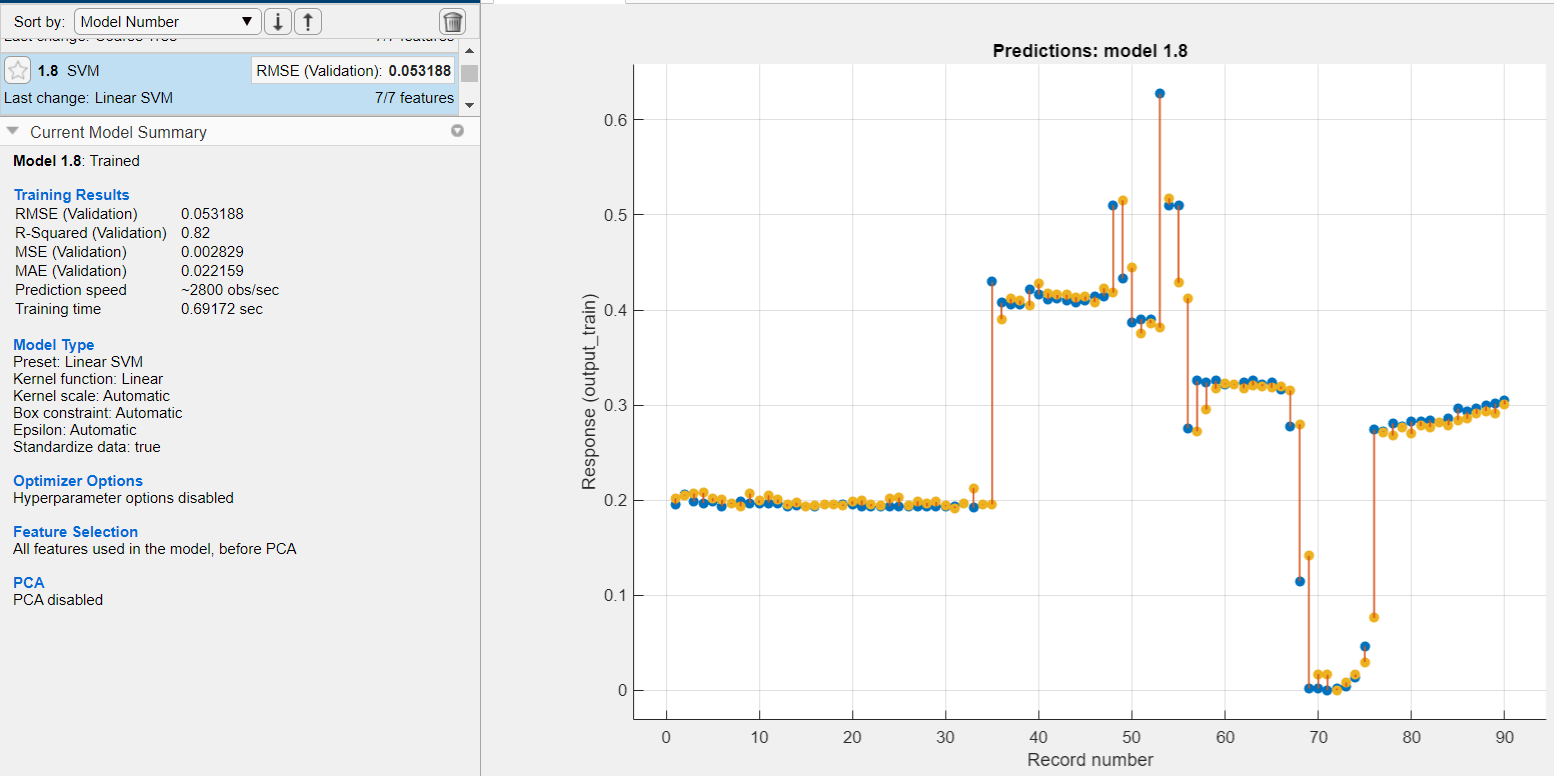

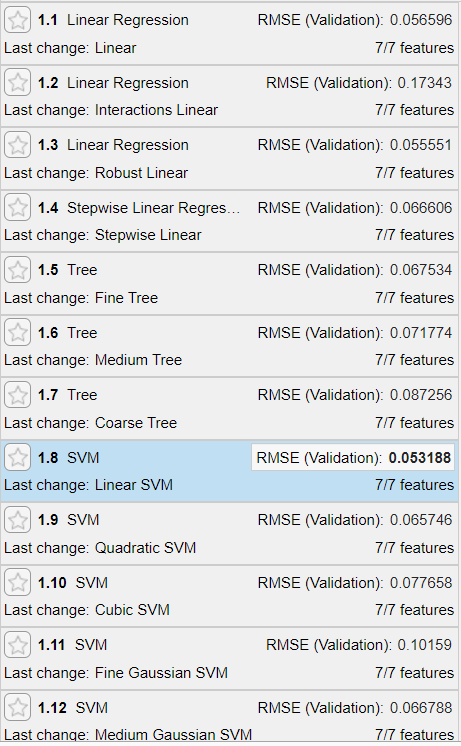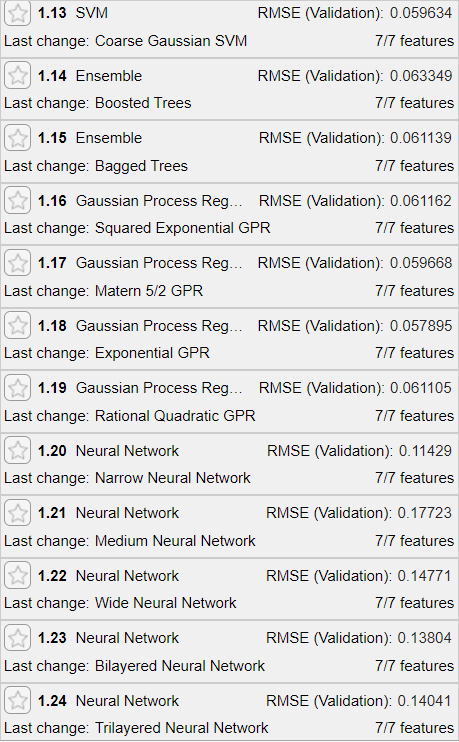

# RMSE (Validation): 1 hour [threshold = 0.750;training_size=0.85;]

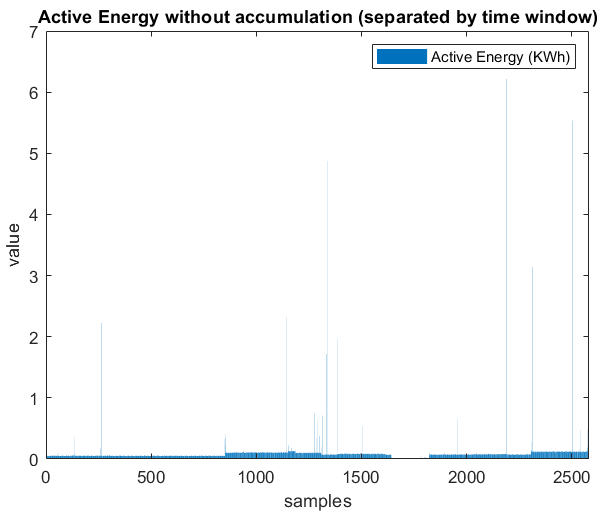

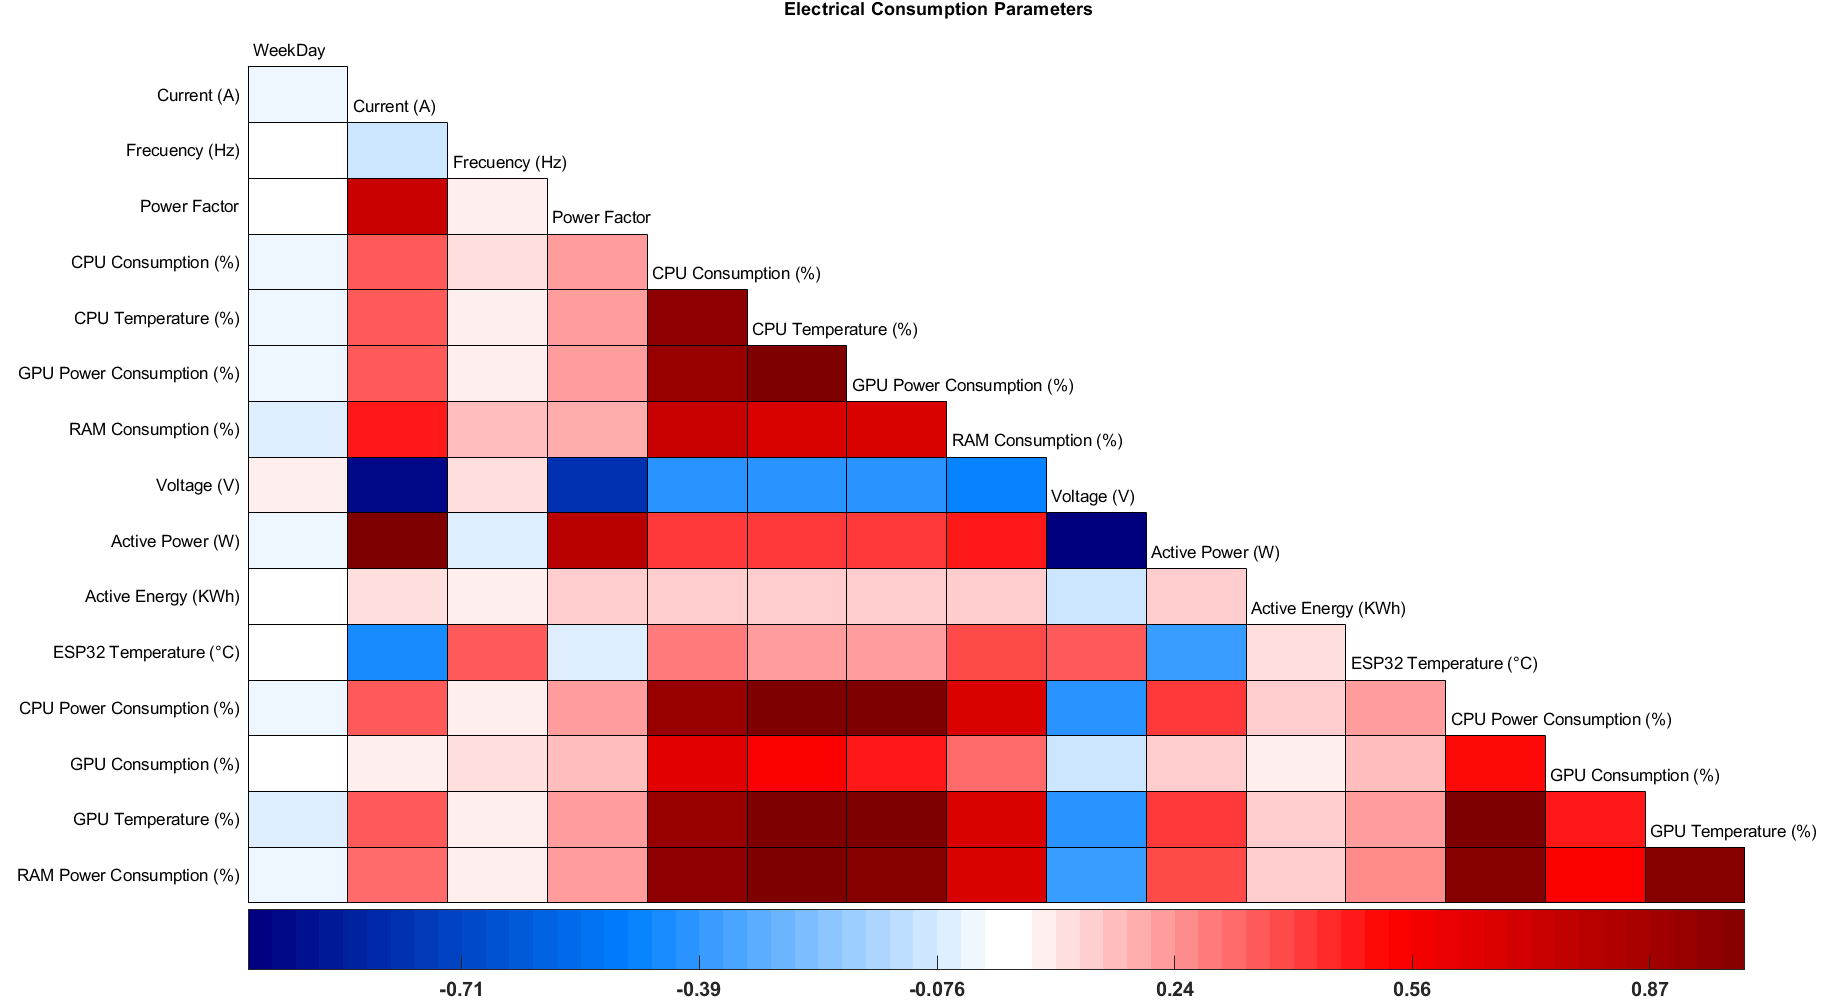

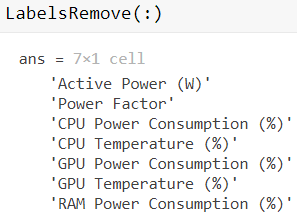

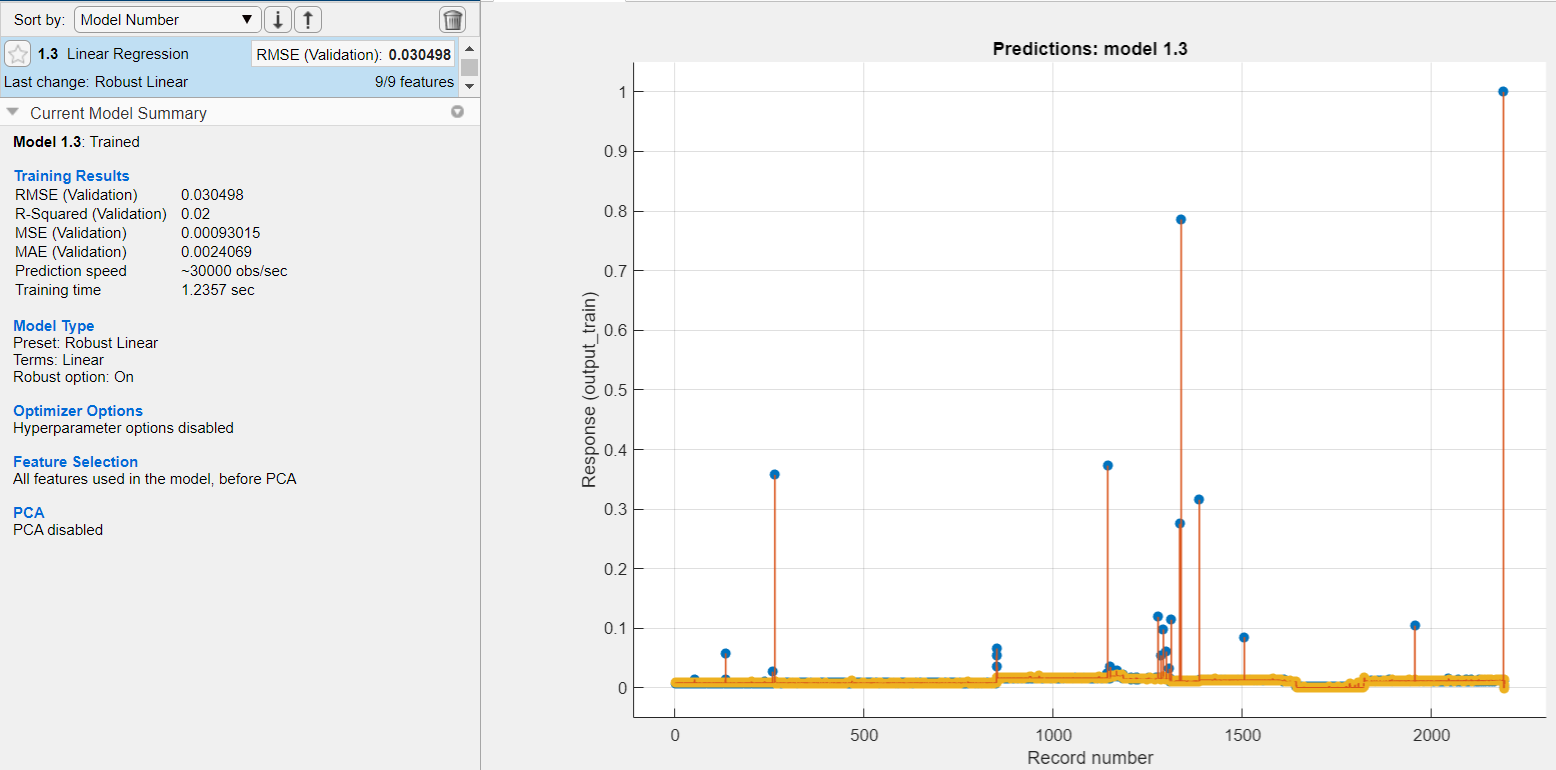

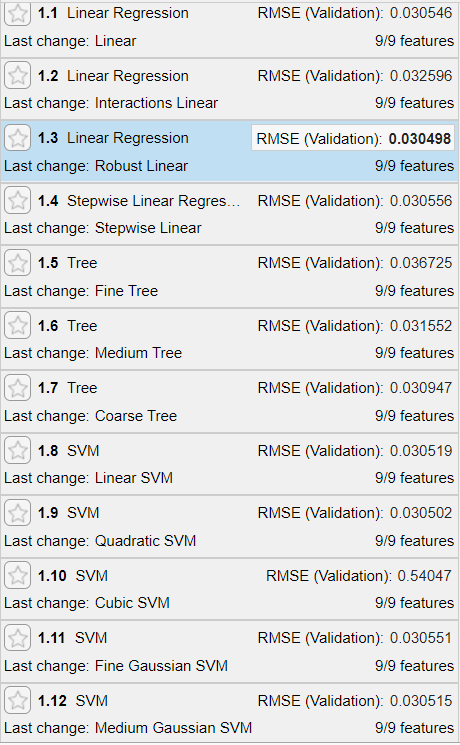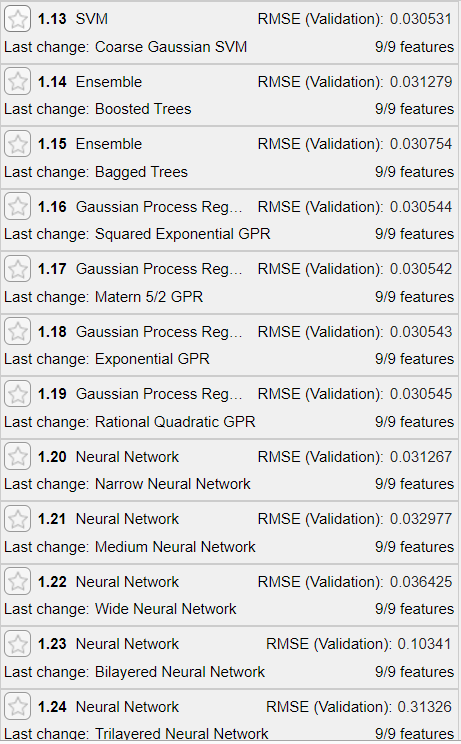

# RMSE (Validation - Filtrado): 1 hour [threshold = 0.750;training_size=0.85;]

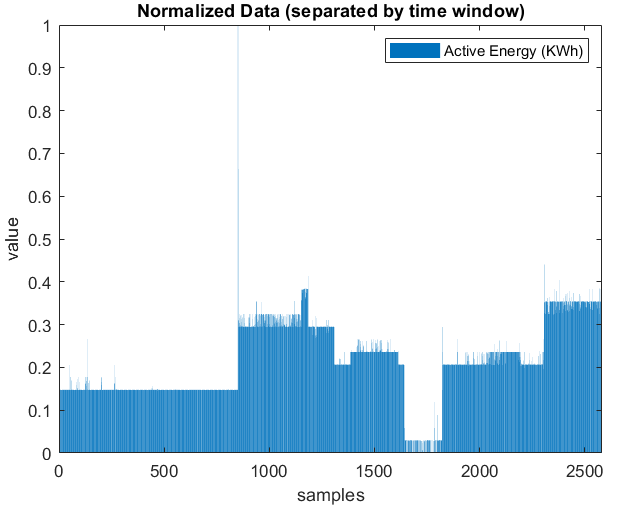

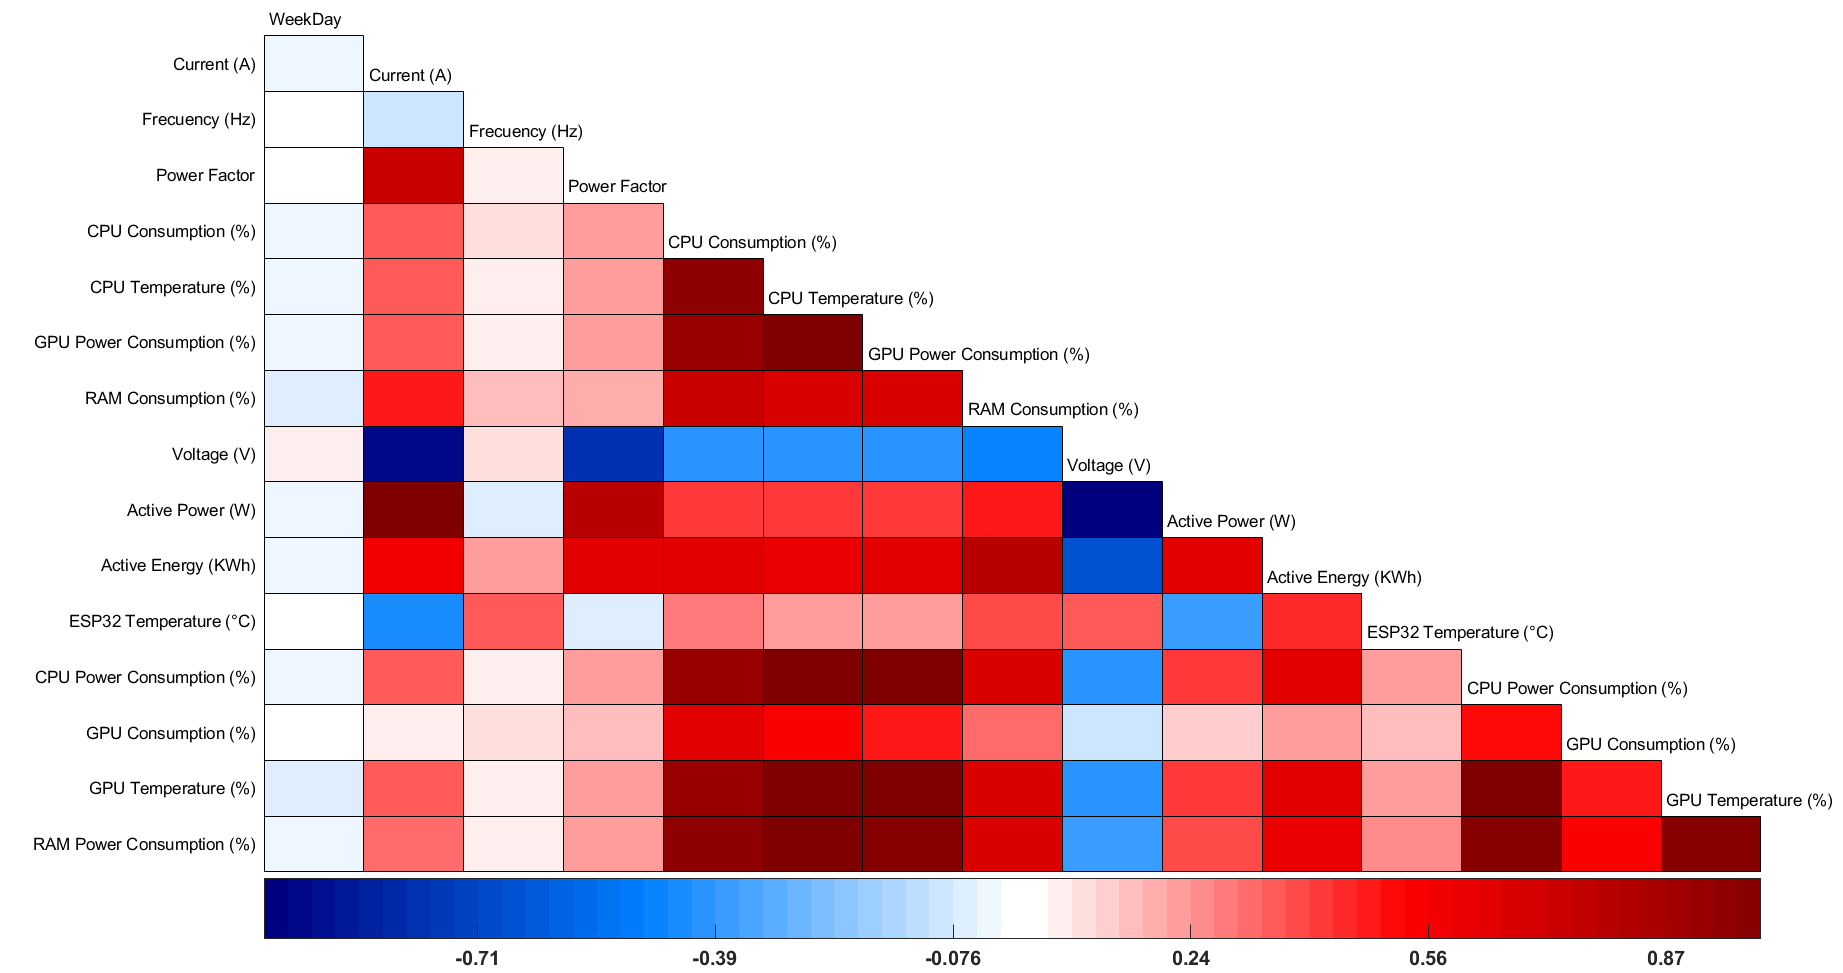

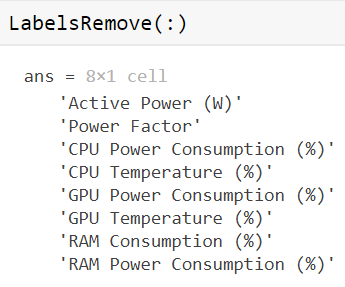

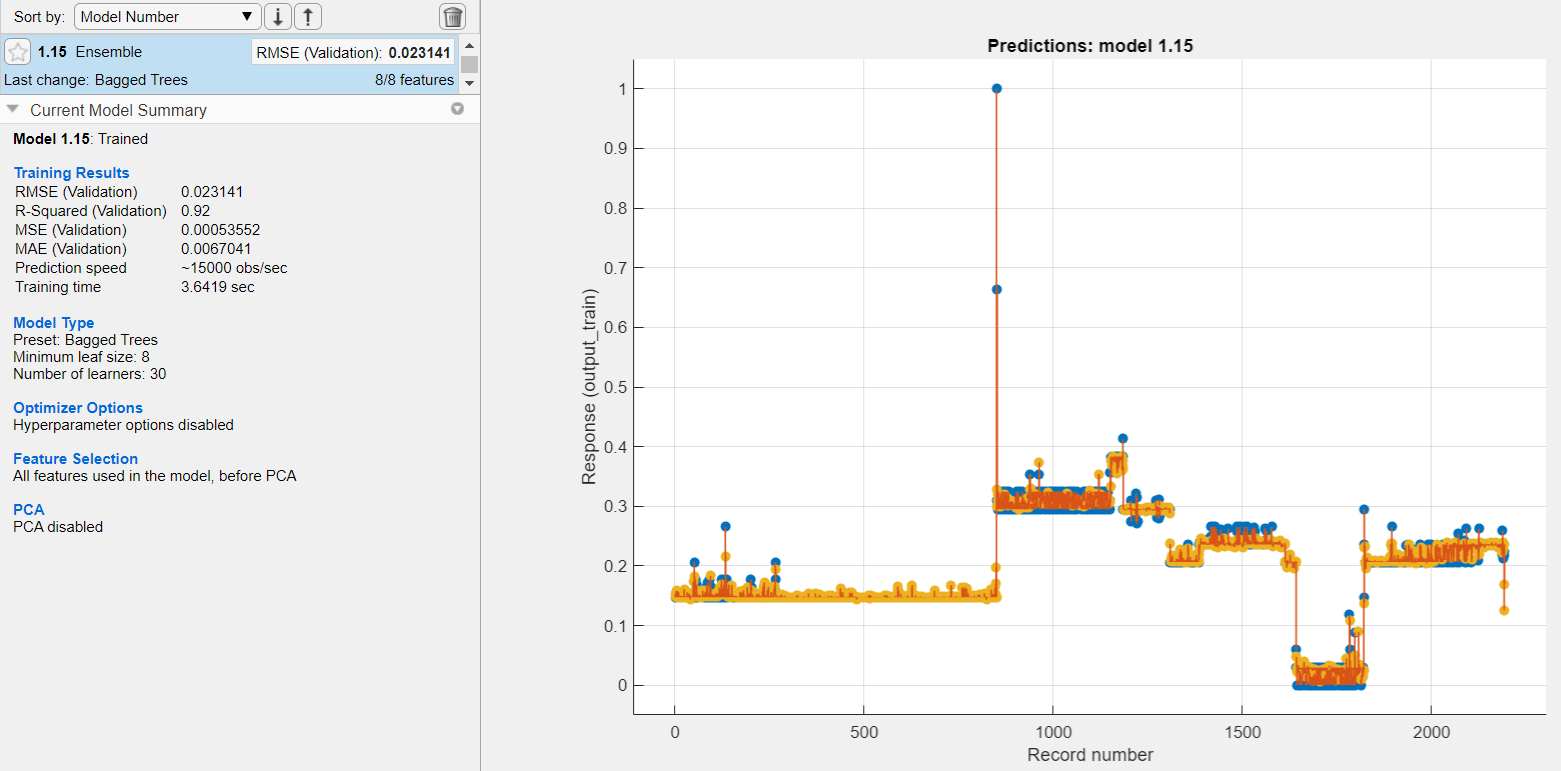

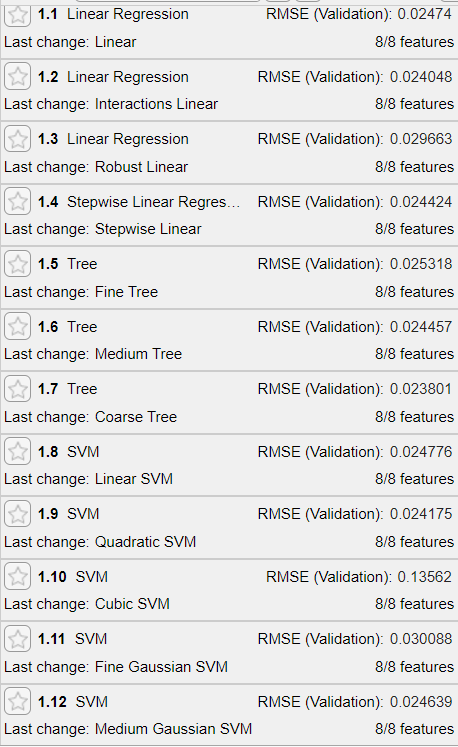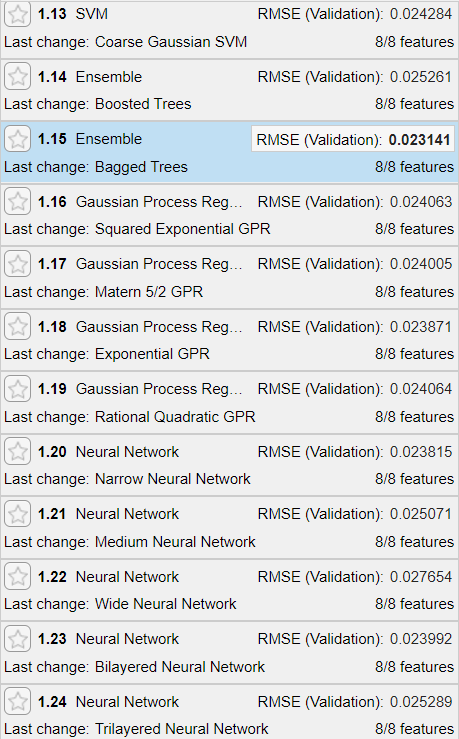

# RMSE (Testing): 1 month [threshold = 0.750;training_size=0.85;]

training_size=0.40;
% input: Energy
input_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size):size(NewDataFeatures,1)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size)+1:size(NewDataFeatures,1)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
[model_month, RMSE_month] = trainRegressionModel_month(input_train, output_train);
RMSE_month

RMSE_month = 0.9105

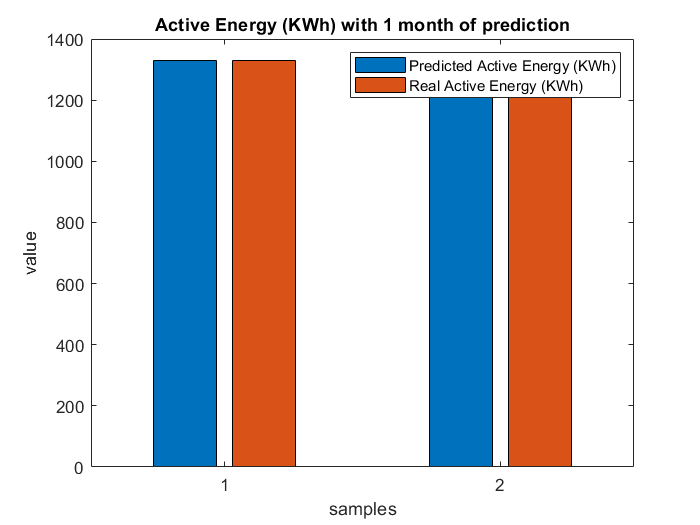

estimate_month=model_month.predictFcn(input_val);
estimate_month=fDenormalize(estimate_month,AEds.max,AEds.min);
output_month=fDenormalize(output_val,AEds.max,AEds.min);
figure; bar([estimate_month,output_month]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 month of prediction');

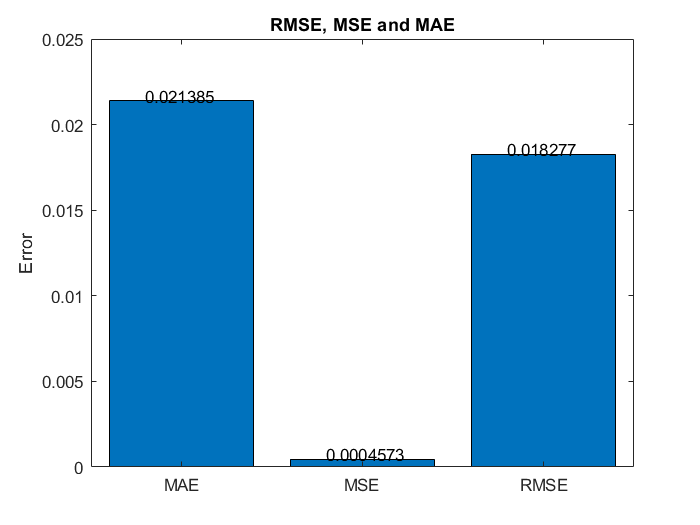

[rmse_month,mse_month,mae_month]=fBar_RmseMseMae(estimate_month,output_month);

save(fullfile(datapath,'rmse_month.mat'),'rmse_month');
save(fullfile(datapath,'mse_month.mat'),'mse_month');
save(fullfile(datapath,'mae_month.mat'),'mae_month');

%figure; plot([estimate_month,output_month]);xlabel('samples');ylabel('value');
%legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
%title('Active Energy (KWh) with 1 month of prediction');
clear model_month output_month estimate_month rmse_month mse_month mae_month RMSE_month

# RMSE (Testing): 1 week [threshold = 0.750;training_size=0.85;]

% input: Energy
input_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size):size(NewDataFeatures,1)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size)+1:size(NewDataFeatures,1)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
%[model_week, RMSE_week] = trainRegressionModel_week(input_train, output_train);
[model_week, RMSE_week] = trainRegressionModel_week_filtered(input_train, output_train);
RMSE_week

RMSE_week = 0.2358

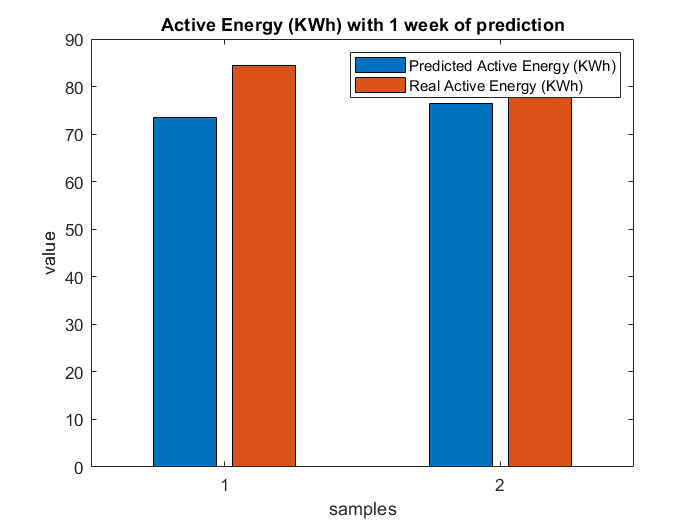

estimate_week=model_week.predictFcn(input_val);
estimate_week=fDenormalize(estimate_week,AEds.max,AEds.min);
output_week=fDenormalize(output_val,AEds.max,AEds.min);
figure; bar([estimate_week,output_week]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 week of prediction');

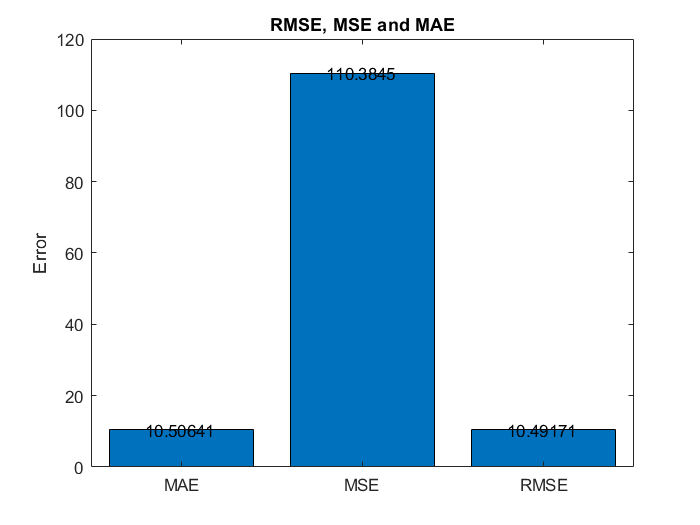

rmse_week = 10.5064

mse_week = 110.3845

mae_week = 10.4917

[rmse_week,mse_week,mae_week]=fBar_RmseMseMae(estimate_week,output_week)

save(fullfile(datapath,'rmse_week.mat'),'rmse_week');
save(fullfile(datapath,'mse_week.mat'),'mse_week');
save(fullfile(datapath,'mae_week.mat'),'mae_week');

%figure; plot([estimate_week,output_week]);xlabel('samples');ylabel('value');
%legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
%title('Active Energy (KWh) with 1 week of prediction');
clear model_week output_week estimate_week rmse_week mse_week mae_week RMSE_week

# RMSE (Testing): 1 day [threshold = 0.750;training_size=0.85;]

% input: Energy
input_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size):size(NewDataFeatures,1)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size)+1:size(NewDataFeatures,1)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
%[model_day, RMSE_day] = trainRegressionModel_day(input_train, output_train);
[model_day, RMSE_day] = trainRegressionModel_day_filtered(input_train, output_train);
RMSE_day

RMSE_day = 0.0535

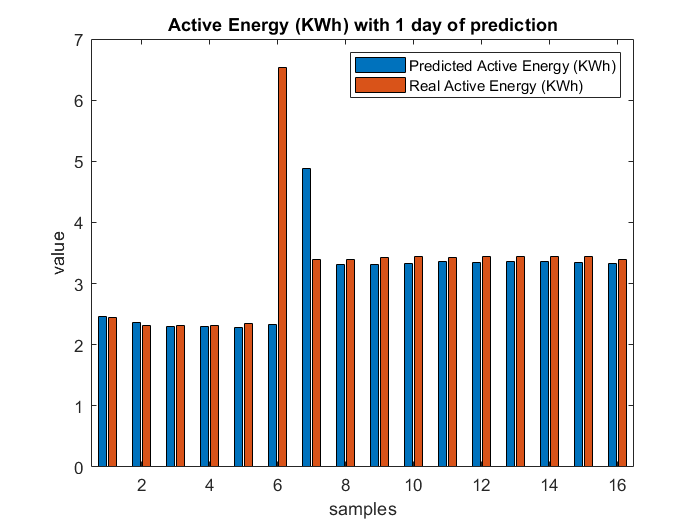

estimate_day=model_day.predictFcn(input_val);
estimate_day=fDenormalize(estimate_day,AEds.max,AEds.min);
output_day=fDenormalize(output_val,AEds.max,AEds.min);
figure; bar([estimate_day,output_day]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 day of prediction');

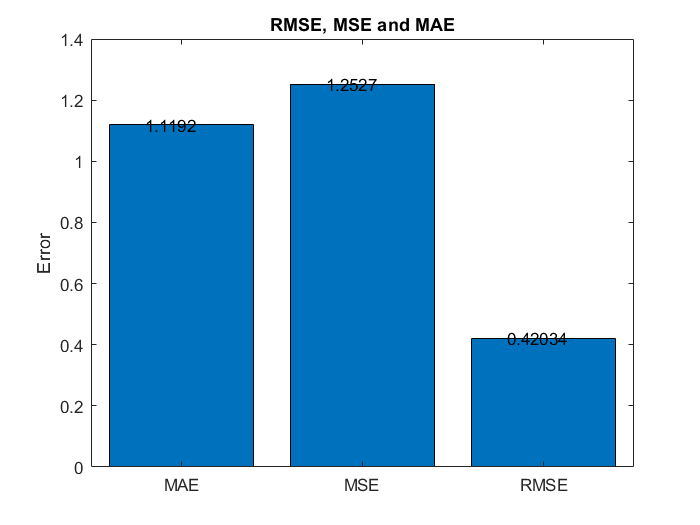

[rmse_day,mse_day,mae_day]=fBar_RmseMseMae(estimate_day,output_day);

save(fullfile(datapath,'rmse_day.mat'),'rmse_day');
save(fullfile(datapath,'mse_day.mat'),'mse_day');
save(fullfile(datapath,'mae_day.mat'),'mae_day');

%figure; plot([estimate_day,output_day]);xlabel('samples');ylabel('value');
%legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
%title('Active Energy (KWh) with 1 day of prediction');
clear model_day output_day estimate_day rmse_day mse_day mae_day RMSE_day

# RMSE (Testing): 1 hour [threshold = 0.750;training_size=0.85;]

% input: Energy
input_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size):size(NewDataFeatures,1)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size)+1:size(NewDataFeatures,1)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
%[model_hour, RMSE_hour] = trainRegressionModel_hour(input_train, output_train);
[model_hour, RMSE_hour] = trainRegressionModel_hour_filtered(input_train, output_train);
RMSE_hour

RMSE_hour = 0.0232

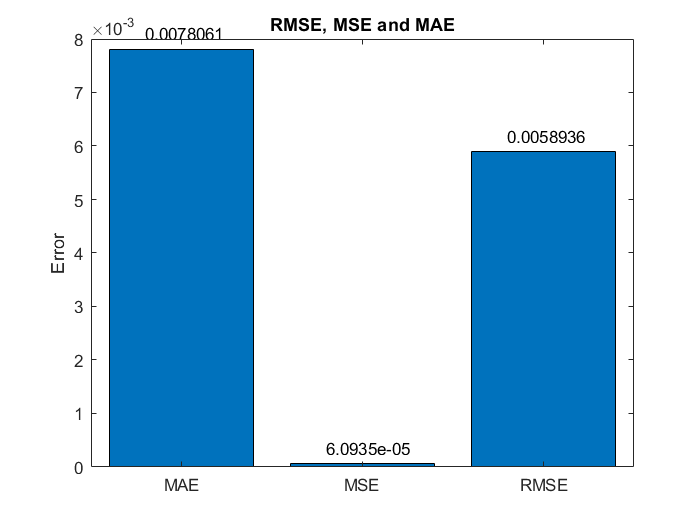

estimate_hour=model_hour.predictFcn(input_val);
estimate_hour=fDenormalize(estimate_hour,AEds.max,AEds.min);
output_hour=fDenormalize(output_val,AEds.max,AEds.min);
%figure; bar([estimate_hour,output_hour]);xlabel('samples');ylabel('value');
%legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
%title('Active Energy (KWh) with 1 hour of prediction');
[rmse_hour,mse_hour,mae_hour]=fBar_RmseMseMae(estimate_hour,output_hour);

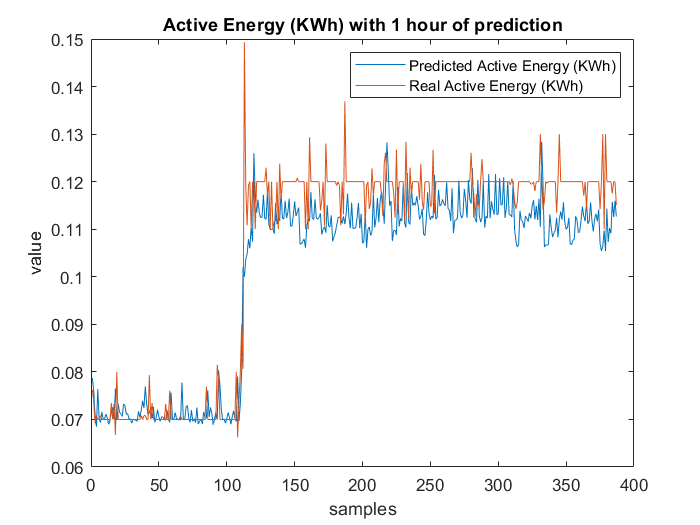

save(fullfile(datapath,'rmse_hour.mat'),'rmse_hour');
save(fullfile(datapath,'mse_hour.mat'),'mse_hour');
save(fullfile(datapath,'mae_hour.mat'),'mae_hour');

figure; plot([estimate_hour,output_hour]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 hour of prediction');

clear model_hour output_hour estimate_hour rmse_hour mse_hour mae_hour RMSE_hour

# RMSE (Testing): minute [threshold = 0.750;training_size=0.85;]

% input: Energy
input_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size):size(NewDataFeatures,1)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size)+1:size(NewDataFeatures,1)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
[model_minute, RMSE_minute] = trainRegressionModel_minute(input_train, output_train);
RMSE_minute

RMSE_minute = 0.0305

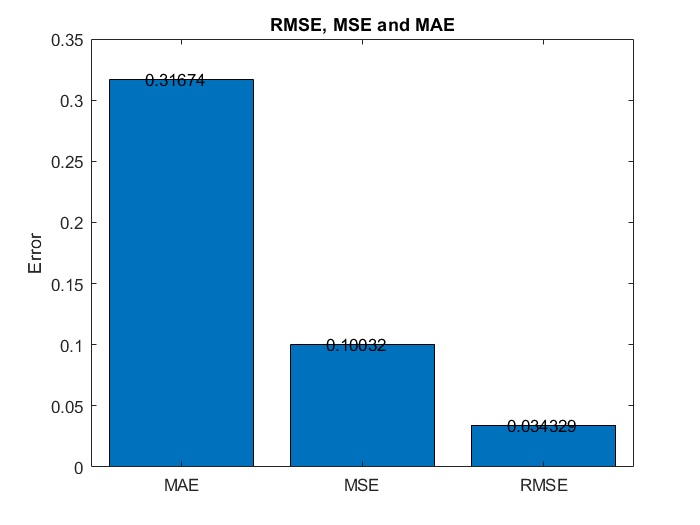

estimate_minute=model_minute.predictFcn(input_val);
estimate_minute=fDenormalize(estimate_minute,AEds.max,AEds.min);
output_minute=fDenormalize(output_val,AEds.max,AEds.min);
%figure; bar([estimate_minute,output_minute]);xlabel('samples');ylabel('value');
%legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
%title('Active Energy (KWh) with 1 minute of prediction');
[rmse_minute,mse_minute,mae_minute]=fBar_RmseMseMae(estimate_minute,output_minute);

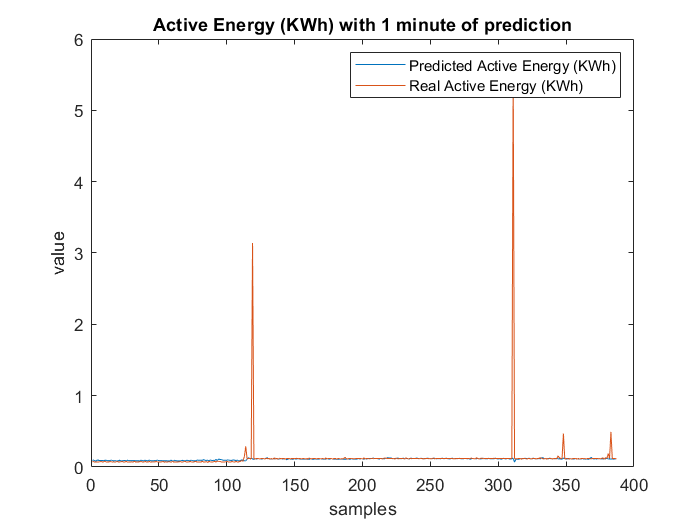

save(fullfile(datapath,'rmse_minute.mat'),'rmse_minute');
save(fullfile(datapath,'mse_minute.mat'),'mse_minute');
save(fullfile(datapath,'mae_minute.mat'),'mae_minute');

figure; plot([estimate_minute,output_minute]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 minute of prediction');

clear model_minute output_minute estimate_minute rmse_minute mse_minute mae_minute RMSE_minute

# Summary RMSE (Testing): Week, Day, Hour and Min [threshold = 0.750;training_size=0.85;]

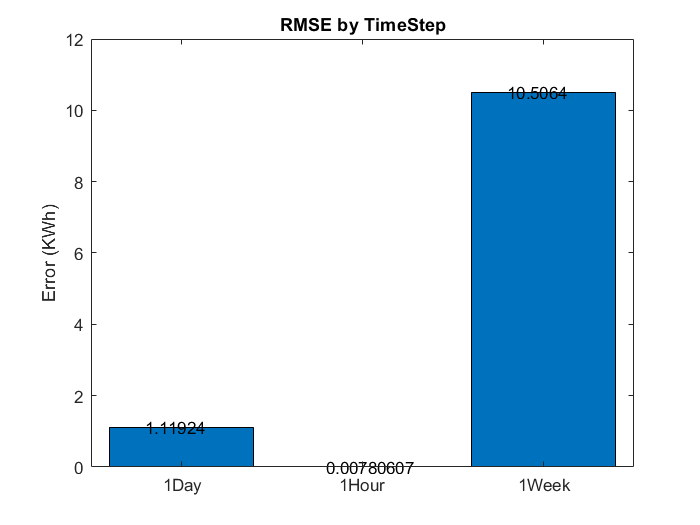

%Month
rmse_month = load(fullfile(datapath,'rmse_month.mat'));rmse_month=rmse_month.rmse_month;
mse_month = load(fullfile(datapath,'mse_month.mat'));mse_month=mse_month.mse_month;
mae_month = load(fullfile(datapath,'mae_month.mat'));mae_month=mae_month.mae_month;
%Week
rmse_week = load(fullfile(datapath,'rmse_week.mat'));rmse_week=rmse_week.rmse_week;
mse_week = load(fullfile(datapath,'mse_week.mat'));mse_week=mse_week.mse_week;
mae_week = load(fullfile(datapath,'mae_week.mat'));mae_week=mae_week.mae_week;
%Day
rmse_day = load(fullfile(datapath,'rmse_day.mat'));rmse_day=rmse_day.rmse_day;
mse_day = load(fullfile(datapath,'mse_day.mat'));mse_day=mse_day.mse_day;
mae_day = load(fullfile(datapath,'mae_day.mat'));mae_day=mae_day.mae_day;
%Hour
rmse_hour = load(fullfile(datapath,'rmse_hour.mat'));rmse_hour=rmse_hour.rmse_hour;
mse_hour = load(fullfile(datapath,'mse_hour.mat'));mse_hour=mse_hour.mse_hour;
mae_hour = load(fullfile(datapath,'mae_hour.mat'));mae_hour=mae_hour.mae_hour;
%Minute
rmse_minute = load(fullfile(datapath,'rmse_minute.mat'));rmse_minute=rmse_minute.rmse_minute;
mse_minute = load(fullfile(datapath,'mse_minute.mat'));mse_minute=mse_minute.mse_minute;
mae_minute = load(fullfile(datapath,'mae_minute.mat'));mae_minute=mae_minute.mae_minute;

%c = categorical({'1Month','1Week','1Day','1Hour','1Min'});
%values = [rmse_month rmse_week rmse_day rmse_hour rmse_minute];%rmse
c = categorical({'1Week','1Day','1Hour'});
values = [rmse_week rmse_day rmse_hour];%rmse
figure;
b=bar(c,values);
ylabel('Error (KWh)')
title('RMSE by TimeStep')
xtips1 = b(1).XEndPoints - 0.2;
ytips1 = b(1).YEndPoints + 0.0003;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'VerticalAlignment','middle')

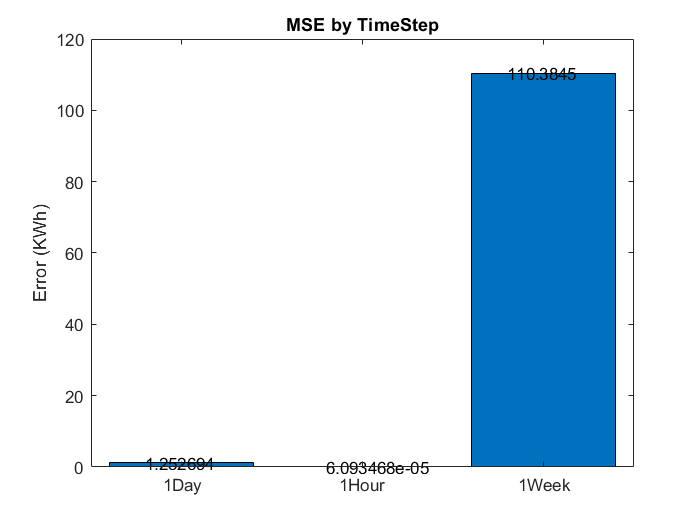

%values = [mse_month mse_week mse_day mse_hour mse_minute];%mse
values = [mse_week mse_day mse_hour];%mse
figure;
b=bar(c,values);
ylabel('Error (KWh)')
title('MSE by TimeStep')
xtips1 = b(1).XEndPoints - 0.2;
ytips1 = b(1).YEndPoints + 0.0003;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'VerticalAlignment','middle')

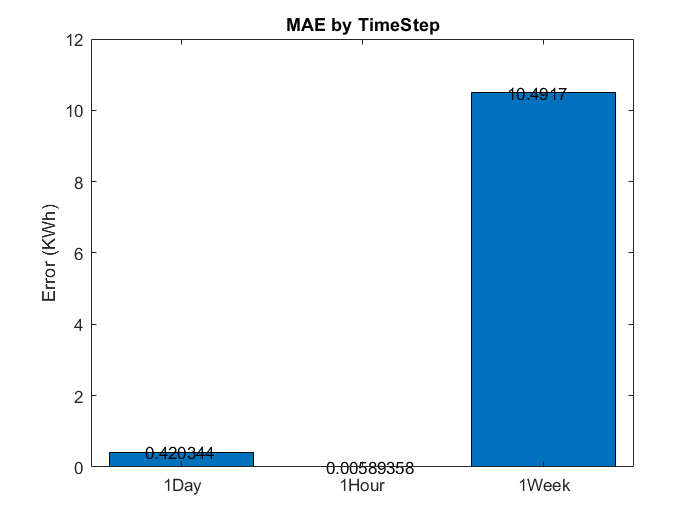

%values = [mae_month mae_week mae_day mae_hour mae_minute];%1-R2
values = [mae_week mae_day mae_hour];%1-R2
figure;
b=bar(c,values);
ylabel('Error (KWh)')
title('MAE by TimeStep')
xtips1 = b(1).XEndPoints - 0.2;
ytips1 = b(1).YEndPoints + 0.0003;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'VerticalAlignment','middle')

# FutureWork

%Continue to record more data on more workstations.
%Create a model for estimating memory and CPU consumption since there are spaces without these values.
%Make a real time consumption prediction system.